
% 参数设置
N = 9;  % 无人机数量（不包括中心无人机）
dt = 0.001;  % 时间步长
prediction_horizon = 30;  % 预测时域长度
lambda_r = 0.1;  % 径向控制输入权重
lambda_theta = 0.05;  % 角度控制输入权重
max_iter = 200;  % 最大迭代次数

% 初始位置（极坐标）
positions = [
    100, 0;
     98, 40.10;
    112, 80.21;
    105, 119.75;
     98, 159.86;
    112, 199.96;
    105, 240.07;
     98, 280.17;
    112, 320.28
];
% 理想位置（圆形编队）
ideal_positions = [
    100, 0;
    100, 40;
    100, 80;
    100, 120;
    100, 160;
    100, 200;
    100, 240;
    100, 280;
    100, 320
];
% 理想位置
ideal_theta = linspace(0, 320, N);  % 理想角度位置
ideal_radius = 100;  % 理想半径

% 系统模型
A = eye(2);
B = eye(2) * dt;

% 目标函数
% function cost = objective(u, x0, x_ideal, A, B, N, dt, lambda_r, lambda_theta)
%     cost = 0;
%     x = x0;
%     for k = 1:N
%         u_k = u(2*k-1:2*k);
%         x = A * x + B * u_k;
%         cost = cost + sum((x - x_ideal).^2) + lambda_r * u_k(1)^2 + lambda_theta * u_k(2)^2;
%     end
% end
% 修复目标函数以确保它返回一个标量值
function cost = objective(u, x0, x_ideal, A, B, N, dt, lambda_r, lambda_theta)
    cost = 0;
    x = x0;
    for k = 1:N
        u_k = u(2*k-1:2*k);
        
        x = A * x + B * u_k;
        
        x =x(1);
        
        % 确保成本是累加的标量值
        cost = cost + sum((x - x_ideal).^2) + lambda_r * u_k(1)^2 + lambda_theta * u_k(2)^2;
    end
    
end

% 约束条件
lb = -ones(2 * prediction_horizon, 1);
ub = ones(2 * prediction_horizon, 1);

% 计算方向信息
function angles = calculate_angles(positions, i, selected_indices)
    % 计算无人机i接收到的方向信息（夹角）
    
    angles = zeros(1, numel(selected_indices));
    for j = 2:numel(selected_indices)
        % delta_x = positions(selected_indices(j), 1) - positions(i, 1);
        % delta_y = positions(selected_indices(j), 2) - positions(i, 2);
        % angles(j) = atan2(delta_y, delta_x);
        delta_x = positions(selected_indices(j),1)*cosd(positions(selected_indices(j),2)) - positions(i,1)*cosd(positions(i,2));
        delta_y = positions(selected_indices(j),1)*sind(positions(selected_indices(j),2)) - positions(i,1)*sind(positions(i,2));
        delta_x0 = 0-positions(i,1)*cosd(positions(i,2));
        delta_y0 = -positions(i,1)*cosd(positions(i,2));
        % delta_x1 = 100 - -positions(i,1)*cosd(positions(i,2));
        % delta_y1 = -positions(i,1)*cosd(positions(i,2));
        % angles(j,1) = [delta_x0,delta_y0]*[delta_x1,delta_y1]'/(norm([delta_x0.delta_y0])*norm([delta_x1,delta_y1]));
        % 修改 calculate_angles 函数中的错误行
angles(j) = [delta_x,delta_y]*[delta_x0,delta_y0]'/(norm([delta_x0,delta_y0])*norm([delta_x,delta_y]));
    end
end

% 计算位置误差
function position = calculate_position_from_angles(selected_positions, angles)
    % for i = 1:9
    % sol_row = [-(r*sin(a2 - theta_n)*sqrt(-(cos(4*a1 + 2*a2 + 2*theta_n) + 6*cos(2*a1 + 2*a2) + 6*cos(2*a1 + 2*theta_n) + cos(2*a2 - 2*theta_n) + 16*cos(2*a1 + a2 + theta_n) + 24*cos(a1 + a2) + 24*cos(a1 + theta_n) + 4*cos(a1 - a2 + 2*theta_n) + 4*cos(a1 + 2*a2 - theta_n) + 4*cos(3*a1 + a2 + 2*theta_n) + 4*cos(3*a1 + 2*a2 + theta_n) + 16*cos(a2 - theta_n) + 18)/(cos(2*a1) - cos(2*a1 + 2*a2 - theta_n) + cos(2*a1 + 2*a2) + cos(2*a2 - theta_n) + cos(theta_n) - cos(2*a1 + theta_n) - 2)))/(cos(2*a1 + a2 + theta_n) + 2*cos(a1 + a2) + 2*cos(a1 + theta_n) + cos(a2 - theta_n) + 2); (r*sin(a2 - theta_n)*sqrt(-(cos(4*a1 + 2*a2 + 2*theta_n) + 6*cos(2*a1 + 2*a2) + 6*cos(2*a1 + 2*theta_n) + cos(2*a2 - 2*theta_n) + 16*cos(2*a1 + a2 + theta_n) + 24*cos(a1 + a2) + 24*cos(a1 + theta_n) + 4*cos(a1 - a2 + 2*theta_n) + 4*cos(a1 + 2*a2 - theta_n) + 4*cos(3*a1 + a2 + 2*theta_n) + 4*cos(3*a1 + 2*a2 + theta_n) + 16*cos(a2 - theta_n) + 18)/(cos(2*a1) - cos(2*a1 + 2*a2 - theta_n) + cos(2*a1 + 2*a2) + cos(2*a2 - theta_n) + cos(theta_n) - cos(2*a1 + theta_n) - 2)))/(cos(2*a1 + a2 + theta_n) + 2*cos(a1 + a2) + 2*cos(a1 + theta_n) + cos(a2 - theta_n) + 2)];
    % sol_theta = [-(r*sin(a2 - theta_n)*sqrt(-(cos(4*a1 + 2*a2 + 2*theta_n) + 6*cos(2*a1 + 2*a2) + 6*cos(2*a1 + 2*theta_n) + cos(2*a2 - 2*theta_n) + 16*cos(2*a1 + a2 + theta_n) + 24*cos(a1 + a2) + 24*cos(a1 + theta_n) + 4*cos(a1 - a2 + 2*theta_n) + 4*cos(a1 + 2*a2 - theta_n) + 4*cos(3*a1 + a2 + 2*theta_n) + 4*cos(3*a1 + 2*a2 + theta_n) + 16*cos(a2 - theta_n) + 18)/(cos(2*a1) - cos(2*a1 + 2*a2 - theta_n) + cos(2*a1 + 2*a2) + cos(2*a2 - theta_n) + cos(theta_n) - cos(2*a1 + theta_n) - 2)))/(cos(2*a1 + a2 + theta_n) + 2*cos(a1 + a2) + 2*cos(a1 + theta_n) + cos(a2 - theta_n) + 2); (r*sin(a2 - theta_n)*sqrt(-(cos(4*a1 + 2*a2 + 2*theta_n) + 6*cos(2*a1 + 2*a2) + 6*cos(2*a1 + 2*theta_n) + cos(2*a2 - 2*theta_n) + 16*cos(2*a1 + a2 + theta_n) + 24*cos(a1 + a2) + 24*cos(a1 + theta_n) + 4*cos(a1 - a2 + 2*theta_n) + 4*cos(a1 + 2*a2 - theta_n) + 4*cos(3*a1 + a2 + 2*theta_n) + 4*cos(3*a1 + 2*a2 + theta_n) + 16*cos(a2 - theta_n) + 18)/(cos(2*a1) - cos(2*a1 + 2*a2 - theta_n) + cos(2*a1 + 2*a2) + cos(2*a2 - theta_n) + cos(theta_n) - cos(2*a1 + theta_n) - 2)))/(cos(2*a1 + a2 + theta_n) + 2*cos(a1 + a2) + 2*cos(a1 + theta_n) + cos(a2 - theta_n) + 2)];
    % end
    
        position = four_a2a3toR(selected_positions(2,1),selected_positions(2,2),selected_positions(3,1),selected_positions(3,2),acos(angles(2)),acos(angles(3)));


end

% MPC控制
for t = 1:max_iter
    % 随机选择最多3架无人机发送信号
    selected_indices = randsample(N,2);
    selected_indices = [1 , selected_indices'];  % 加上中心无人机FY00
    
    for i = 1:N
        if ismember(i, selected_indices)
            continue;  % 发射信号的无人机不调整位置
        end
        
        % 计算方向信息
        angles = calculate_angles(positions, i, selected_indices);
        
        % 计算当前位置
        fy00_pos = [0, 0];  % 中心无人机位置
        selected_positions = positions(selected_indices, :);
        current_position = calculate_position_from_angles(selected_positions, angles);
        
        % 更新位置
        % 目标函数优化
        u0 = zeros(2 * prediction_horizon, 1);
        x0 = current_position';
        x_ideal = ideal_positions(i, :)';
        options = optimoptions('fmincon', 'Display', 'off');
        u_opt = fmincon(@(u) objective(u, x0, x_ideal, A, B, prediction_horizon, dt, lambda_r, lambda_theta), ...
                        u0, [], [], [], [], lb, ub, [], options);
        
        % 应用控制输入
        positions(i, 1) = positions(i, 1) + u_opt(1) * dt;
        positions(i, 2) = positions(i, 2) + u_opt(2) * dt;
    end
    
    % 打印当前时刻的位置
    fprintf('时间步 %d，位置：\n', t);
    % fprintf('时间步 %d，位置：\n', t);
    % disp(positions);
    [rrrm,tttm] = four_a2a3toR(positions)
    disp(rrrm);
end


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5815.02                        5.44e+03              1
     1          6             2126.62              1         1.64e+03              1
     2          9             1712.49            2.5              342            2.5
     3         12             1259.98           6.25             32.9           6.25
     4         15             441.445         15.625             72.1           15.6
     5         18          0.00754148        22.5995             1.78           39.1
     6         21         1.95424e-15      0.0915337         1.14e-06           56.5
     7         24         1.55298e-25    4.62181e-08          4.9e-11           56.5

方程已解。

fsolve 已完成，因为按照

时间步 1，位置：


  100.0000         0
   97.9990   40.1000
  112.0010   80.2100
  105.0010  119.7500
   98.0010  159.8600
  112.0000  199.9600
  105.0010  240.0700
   98.0010  280.1700
  112.0010  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24484.5                        2.22e+03              1
     1          6             7061.33              1         9.03e+03              1
     2          9             2160.41            2.5         1.01e+03            2.5
     3         12             1410.58           6.25             50.6           6.25
     4         15             272.574         15.625             99.7           15.6
     5         18         1.33612e-10        12.2383         5.24e-05           39.1
     6         21           1.415e-25    8.57147e-06         5.57e-11           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 2，位置：


  100.0000         0
   97.9990   40.1000
  112.0020   80.2100
  105.0020  119.7500
   98.0020  159.8600
  112.0010  199.9600
  105.0020  240.0700
   98.0020  280.1700
  112.0010  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21664.9                        6.77e+03              1
     1          6             4519.22              1         5.81e+03              1
     2          9              2085.9            2.5              848            2.5
     3         12             1930.96           6.25              213           6.25
     4         15             1653.15         15.625              239           15.6
     5         18             928.437        39.0625              545           39.1
     6         21             395.445        97.6563              426           97.7
     7         24           0.0459553        30.0084             8.28           97.7
     8         27         7.59128e-14       0.296608         1.04e-05           97.7
     9         30         1.71656e-26    3.86474e-07         8.4

时间步 3，位置：


  100.0000         0
   97.9980   40.1000
  112.0030   80.2100
  105.0030  119.7500
   98.0020  159.8600
  112.0020  199.9600
  105.0030  240.0700
   98.0020  280.1700
  112.0020  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18878.7                        3.13e+03              1
     1          6             4534.41              1         5.19e+03              1
     2          9             2795.91            2.5              125            2.5
     3         12              2280.7           6.25             39.1           6.25
     4         15             1222.93         15.625              132           15.6
     5         18             8.19128        39.0625             5.11           39.1
     6         21         3.48557e-07        3.47555           0.0265           97.7
     7         24         1.13931e-23    0.000682404         4.96e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 4，位置：


  100.0000         0
   97.9990   40.1000
  112.0040   80.2100
  105.0040  119.7500
   98.0030  159.8600
  112.0030  199.9600
  105.0040  240.0700
   98.0020  280.1700
  112.0020  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17120.1                             398              1
     1          6             5321.28              1         6.45e+03              1
     2          9             2162.85            2.5              453            2.5
     3         12             1639.75           6.25             38.2           6.25
     4         15             879.661         15.625         2.04e+03           15.6
     5         18          7.2164e-05        27.2276            0.668           39.1
     6         21         2.21744e-18     0.00741405         7.62e-08           68.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 5，位置：


  100.0000         0
   98.0000   40.1000
  112.0050   80.2100
  105.0050  119.7500
   98.0040  159.8600
  112.0040  199.9600
  105.0050  240.0700
   98.0020  280.1700
  112.0030  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13196.5                        5.77e+03              1
     1          6             395.549              1              919              1
     2          9             307.111            2.5             9.34            2.5
     3         12             201.862           6.25             7.51           6.25
     4         15             35.1025         15.625             11.7           15.6
     5         18          0.00010022        11.1825             1.42           39.1
     6         21         8.57297e-18     0.00544078         3.38e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 6，位置：


  100.0000         0
   98.0010   40.1000
  112.0040   80.2100
  105.0050  119.7500
   98.0050  159.8600
  112.0050  199.9600
  105.0050  240.0700
   98.0030  280.1700
  112.0040  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12809.1                        4.29e+03              1
     1          6             359.477              1         2.42e+03              1
     2          9             29.4799            2.5             68.5            2.5
     3         12             2.46293           6.25             1.94           6.25
     4         15         4.31565e-06        2.56047            0.227           15.6
     5         18         4.51306e-23     0.00217809         2.04e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 7，位置：


  100.0000         0
   98.0020   40.1000
  112.0050   80.2100
  105.0060  119.7500
   98.0060  159.8600
  112.0060  199.9600
  105.0050  240.0700
   98.0040  280.1700
  112.0050  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17120.7                             398              1
     1          6             5321.53              1         6.45e+03              1
     2          9             2162.58            2.5              453            2.5
     3         12             1639.51           6.25             38.2           6.25
     4         15             886.116         15.625         2.07e+03           15.6
     5         18         8.71816e-05        27.2257            0.744           39.1
     6         21          3.4997e-18      0.0080968         9.01e-08           68.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 8，位置：


  100.0000         0
   98.0030   40.1000
  112.0060   80.2100
  105.0070  119.7500
   98.0070  159.8600
  112.0070  199.9600
  105.0060  240.0700
   98.0040  280.1700
  112.0060  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9577.38                           2e+03              1
     1          6              762.86              1         1.65e+03              1
     2          9             567.529            2.5             43.6            2.5
     3         12             482.917           6.25             49.9           6.25
     4         15             285.393         15.625              157           15.6
     5         18             33.7047        39.0625              537           39.1
     6         21           0.0359022       0.552799             14.4           97.7
     7         24          4.3613e-14       0.162505          1.6e-05           97.7
     8         27         7.43372e-25    1.74796e-07         6.39e-11           97.7



时间步 9，位置：


  100.0000         0
   98.0020   40.1000
  112.0070   80.2100
  105.0080  119.7500
   98.0080  159.8600
  112.0080  199.9600
  105.0070  240.0700
   98.0050  280.1700
  112.0060  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22112.1                        3.16e+03              1
     1          6             5590.98              1         7.69e+03              1
     2          9             1789.47            2.5              119            2.5
     3         12             1596.84           6.25             14.9           6.25
     4         15              1163.9         15.625             12.8           15.6
     5         18             377.556        39.0625             52.7           39.1
     6         21          0.00984474        51.4916              3.8           97.7
     7         24         3.01526e-13       0.250589         3.72e-05            129
     8         27          3.4967e-24    1.26211e-06         2.62e-10            129



时间步 10，位置：


  100.0000         0
   98.0030   40.1000
  112.0080   80.2100
  105.0090  119.7500
   98.0090  159.8600
  112.0090  199.9600
  105.0070  240.0700
   98.0050  280.1700
  112.0070  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10361.1                        1.73e+03              1
     1          6             9968.94              1              788              1
     2          9             9608.46            2.5              333            2.5
     3         12             8858.31           6.25             88.6           6.25
     4         15             7136.02         15.625              101           15.6
     5         18             3629.49        39.0625              212           39.1
     6         21            0.187981        96.8673            0.882           97.7
     7         24         3.97263e-11       0.689931         0.000109            242
     8         27         1.36568e-25    9.93902e-06          4.7e-11            242



时间步 11，位置：


  100.0000         0
   98.0040   40.1000
  112.0090   80.2100
  105.0080  119.7500
   98.0090  159.8600
  112.0090  199.9600
  105.0080  240.0700
   98.0060  280.1700
  112.0080  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9237.38                        1.77e+03              1
     1          6             8531.38              1         1.86e+03              1
     2          9             7476.91            2.5         2.09e+03            2.5
     3         12             5616.94           6.25          2.3e+03           6.25
     4         15             2645.85         15.625         1.77e+03           15.6
     5         18             57.9256        39.0625              132           39.1
     6         21         8.55169e-09        7.62681          0.00175           97.7
     7         24         3.14434e-24    9.23974e-05         1.57e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 12，位置：


  100.0000         0
   98.0030   40.1000
  112.0090   80.2100
  105.0090  119.7500
   98.0100  159.8600
  112.0100  199.9600
  105.0080  240.0700
   98.0070  280.1700
  112.0090  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20468.2                        5.45e+03              1
     1          6               12578              1         5.54e+03              1
     2          9              8816.4            2.5         2.65e+03            2.5
     3         12              7608.7           6.25              928           6.25
     4         15             6410.68         15.625              320           15.6
     5         18             3390.73        39.0625         1.34e+03           39.1
     6         21             374.624        90.7498             82.1           97.7
     7         24            0.169392        20.6766               21           97.7
     8         27          9.8091e-12       0.394137         0.000144           97.7
     9         30         2.12172e-26    3.09243e-06         1.4

时间步 13，位置：


  100.0000         0
   98.0030   40.1000
  112.0100   80.2100
  105.0100  119.7500
   98.0100  159.8600
  112.0110  199.9600
  105.0090  240.0700
   98.0080  280.1700
  112.0100  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2243.21                        2.92e+03              1
     1          6             1723.53              1              431              1
     2          9             1584.36            2.5             99.2            2.5
     3         12              1279.2           6.25              100           6.25
     4         15             637.671         15.625              189           15.6
     5         18             4.92905        36.4975              143           39.1
     6         21         3.88456e-07        2.39286           0.0492           91.2
     7         24         1.93024e-24    0.000602661         5.36e-11           91.2

方程已解。

fsolve 已完成，因为按照

时间步 14，位置：


  100.0000         0
   98.0020   40.1000
  112.0100   80.2100
  105.0110  119.7500
   98.0110  159.8600
  112.0110  199.9600
  105.0100  240.0700
   98.0090  280.1700
  112.0110  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17356.1                        2.87e+03              1
     1          6             13081.9              1         5.96e+03              1
     2          9              5045.9            2.5         4.14e+03            2.5
     3         12              3024.3           6.25         1.34e+03           6.25
     4         15             2052.35         15.625              462           15.6
     5         18               575.8        39.0625              221           39.1
     6         21            0.118535        43.8732             8.39           97.7
     7         24         7.25095e-12       0.604449         9.02e-05            110
     8         27         4.54248e-24     4.6294e-06         2.35e-10            110



时间步 15，位置：


  100.0000         0
   98.0010   40.1000
  112.0090   80.2100
  105.0120  119.7500
   98.0110  159.8600
  112.0120  199.9600
  105.0100  240.0700
   98.0100  280.1700
  112.0120  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20467.6                        5.45e+03              1
     1          6             12576.9              1         5.54e+03              1
     2          9             8815.92            2.5         2.65e+03            2.5
     3         12             7608.44           6.25              928           6.25
     4         15             6410.39         15.625              321           15.6
     5         18             3390.38        39.0625         1.34e+03           39.1
     6         21             374.437        90.7417             81.9           97.7
     7         24            0.169187        20.6719               21           97.7
     8         27         9.77455e-12       0.393899         0.000144           97.7
     9         30         3.09297e-25    3.08755e-06         5.6

时间步 16，位置：


  100.0000         0
   98.0010   40.1000
  112.0100   80.2100
  105.0130  119.7500
   98.0110  159.8600
  112.0130  199.9600
  105.0110  240.0700
   98.0110  280.1700
  112.0130  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13550.4                        2.13e+03              1
     1          6             12329.1              1         2.38e+03              1
     2          9               11097            2.5         1.75e+03            2.5
     3         12             9709.98           6.25         1.13e+03           6.25
     4         15             7072.34         15.625              902           15.6
     5         18             2188.08        39.0625              747           39.1
     6         21             3.10262        48.0063               23           97.7
     7         24         2.31033e-07        1.71946           0.0211            120
     8         27         2.15208e-24    0.000443122         1.61e-10            120



时间步 17，位置：


  100.0000         0
   98.0020   40.1000
  112.0100   80.2100
  105.0140  119.7500
   98.0120  159.8600
  112.0140  199.9600
  105.0120  240.0700
   98.0110  280.1700
  112.0140  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9966.75                             519              1
     1          6             8992.91              1         2.91e+03              1
     2          9             2122.93            2.5         2.15e+03            2.5
     3         12             1650.41           6.25              159           6.25
     4         15             1271.52         15.625              293           15.6
     5         18             360.088        39.0625              862           39.1
     6         21               101.6        29.0085              248           97.7
     7         24         0.000633134        9.31631            0.821           97.7
     8         27         1.56872e-19      0.0220643          1.4e-08           97.7



时间步 18，位置：


  100.0000         0
   98.0010   40.1000
  112.0110   80.2100
  105.0140  119.7500
   98.0130  159.8600
  112.0150  199.9600
  105.0130  240.0700
   98.0120  280.1700
  112.0140  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               10362                        1.73e+03              1
     1          6              9969.9              1              789              1
     2          9             9609.39            2.5              333            2.5
     3         12             8859.19           6.25             88.6           6.25
     4         15             7136.76         15.625              101           15.6
     5         18             3629.94        39.0625              212           39.1
     6         21            0.187956        96.8705            0.882           97.7
     7         24         3.97327e-11       0.689867         0.000109            242
     8         27         2.33301e-25    9.93992e-06         6.12e-11            242



时间步 19，位置：


  100.0000         0
   98.0020   40.1000
  112.0120   80.2100
  105.0130  119.7500
   98.0130  159.8600
  112.0150  199.9600
  105.0140  240.0700
   98.0130  280.1700
  112.0150  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               10362                        1.73e+03              1
     1          6             9969.85              1              789              1
     2          9             9609.35            2.5              333            2.5
     3         12             8859.15           6.25             88.6           6.25
     4         15             7136.74         15.625              101           15.6
     5         18             3629.93        39.0625              212           39.1
     6         21            0.187955        96.8708            0.882           97.7
     7         24         3.97401e-11       0.689867         0.000109            242
     8         27         1.22179e-25    9.94044e-06         4.44e-11            242



时间步 20，位置：


  100.0000         0
   98.0030   40.1000
  112.0130   80.2100
  105.0120  119.7500
   98.0130  159.8600
  112.0150  199.9600
  105.0150  240.0700
   98.0140  280.1700
  112.0160  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13198.9                        5.77e+03              1
     1          6             395.611              1              919              1
     2          9             307.163            2.5             9.34            2.5
     3         12             201.902           6.25             7.51           6.25
     4         15             35.1167         15.625             11.7           15.6
     5         18         0.000100247        11.1845             1.42           39.1
     6         21         8.76001e-18     0.00543963         3.42e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 21，位置：


  100.0000         0
   98.0040   40.1000
  112.0120   80.2100
  105.0120  119.7500
   98.0140  159.8600
  112.0160  199.9600
  105.0150  240.0700
   98.0150  280.1700
  112.0170  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               12365                        5.63e+03              1
     1          6             744.524              1         2.25e+03              1
     2          9             283.168            2.5              132            2.5
     3         12             103.077           6.25             10.8           6.25
     4         15         6.27383e-05        9.55221             0.16           15.6
     5         18         1.30682e-22      0.0073429         1.43e-09           23.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 22，位置：


  100.0000         0
   98.0050   40.1000
  112.0110   80.2100
  105.0130  119.7500
   98.0140  159.8600
  112.0170  199.9600
  105.0160  240.0700
   98.0160  280.1700
  112.0180  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21872.8                        3.82e+03              1
     1          6             18095.8              1         4.96e+03              1
     2          9             14106.3            2.5         3.76e+03            2.5
     3         12             11536.1           6.25         1.99e+03           6.25
     4         15             8923.33         15.625              368           15.6
     5         18             4175.76        39.0625         1.06e+03           39.1
     6         21             76.2782        79.3355               42           97.7
     7         24          0.00127824        9.14804              1.4            198
     8         27         3.86848e-18      0.0354758         6.91e-08            198



时间步 23，位置：


  100.0000         0
   98.0050   40.1000
  112.0120   80.2100
  105.0140  119.7500
   98.0147  159.8600
  112.0170  199.9600
  105.0170  240.0700
   98.0170  280.1700
  112.0190  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               25836                        2.99e+03              1
     1          6                7268              1         9.47e+03              1
     2          9             1766.63            2.5              725            2.5
     3         12             1228.19           6.25             37.4           6.25
     4         15             343.082         15.625              359           15.6
     5         18         6.03383e-05        17.1777             1.06           39.1
     6         21         6.78397e-18     0.00232552         1.03e-07           42.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 24，位置：


  100.0000         0
   98.0050   40.1000
  112.0130   80.2100
  105.0140  119.7500
   98.0157  159.8600
  112.0160  199.9600
  105.0180  240.0700
   98.0180  280.1700
  112.0200  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20468.9                        5.46e+03              1
     1          6             12577.7              1         5.54e+03              1
     2          9             8816.56            2.5         2.65e+03            2.5
     3         12             7609.02           6.25              928           6.25
     4         15              6410.9         15.625              321           15.6
     5         18             3390.74        39.0625         1.34e+03           39.1
     6         21              374.48         90.747               82           97.7
     7         24            0.169216        20.6731               21           97.7
     8         27         9.78273e-12       0.393932         0.000144           97.7
     9         30         2.96915e-25    3.08896e-06         5.4

时间步 25，位置：


  100.0000         0
   98.0050   40.1000
  112.0140   80.2100
  105.0150  119.7500
   98.0157  159.8600
  112.0170  199.9600
  105.0190  240.0700
   98.0190  280.1700
  112.0210  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10808.7                         8.2e+03              1
     1          6             3469.62              1         1.86e+03              1
     2          9             3178.43            2.5              380            2.5
     3         12             2992.95           6.25             95.4           6.25
     4         15             2571.98         15.625             66.2           15.6
     5         18             1654.14        39.0625              108           39.1
     6         21               229.9        97.6562              104           97.7
     7         24          0.00998479        57.4593             4.11            244
     8         27          7.1303e-15        0.35713         4.15e-06            244
     9         30         3.01509e-24    2.95091e-07         1.9

时间步 26，位置：


  100.0000         0
   98.0040   40.1000
  112.0150   80.2100
  105.0160  119.7500
   98.0167  159.8600
  112.0170  199.9600
  105.0190  240.0700
   98.0200  280.1700
  112.0220  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4246.48                             989              1
     1          6             3945.69              1              624              1
     2          9             3609.79            2.5              220            2.5
     3         12              2949.1           6.25              228           6.25
     4         15             1443.29         15.625              729           15.6
     5         18              64.166         33.494             25.6           39.1
     6         21         0.000194423        5.94501            0.161           83.7
     7         24         4.18193e-20      0.0102823         1.93e-09           83.7

方程已解。

fsolve 已完成，因为按照

时间步 27，位置：


  100.0000         0
   98.0030   40.1000
  112.0150   80.2100
  105.0170  119.7500
   98.0177  159.8600
  112.0160  199.9600
  105.0180  240.0700
   98.0210  280.1700
  112.0230  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21672.3                        6.77e+03              1
     1          6             4521.25              1         5.82e+03              1
     2          9             2086.77            2.5              848            2.5
     3         12             1931.79           6.25              213           6.25
     4         15             1653.91         15.625              239           15.6
     5         18             928.998        39.0625              545           39.1
     6         21               395.1        97.6563              426           97.7
     7         24           0.0454718        29.9912             8.24           97.7
     8         27         7.38621e-14       0.295035         1.02e-05           97.7
     9         30         1.42515e-24    3.80842e-07         7.8

时间步 28，位置：


  100.0000         0
   98.0020   40.1000
  112.0160   80.2100
  105.0180  119.7500
   98.0177  159.8600
  112.0170  199.9600
  105.0190  240.0700
   98.0210  280.1700
  112.0240  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8206.81                        3.01e+03              1
     1          6             122.108              1              311              1
     2          9             109.721            2.5             11.8            2.5
     3         12              92.121           6.25             21.3           6.25
     4         15             51.6496         15.625              107           15.6
     5         16             51.6496        39.0625              107           39.1
     6         19             29.0142        9.76562             63.6           9.77
     7         22             14.4153        24.4141              313           24.4
     8         25          0.00262055        1.12427             3.95           24.4
     9         28         2.24991e-17      0.0415907          3.

时间步 29，位置：


  100.0000         0
   98.0010   40.1000
  112.0170   80.2100
  105.0180  119.7500
   98.0187  159.8600
  112.0180  199.9600
  105.0200  240.0700
   98.0220  280.1700
  112.0250  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22118.6                        3.16e+03              1
     1          6             5592.07              1         7.69e+03              1
     2          9              1789.7            2.5              119            2.5
     3         12             1597.04           6.25             14.9           6.25
     4         15             1164.03         15.625             12.8           15.6
     5         18             377.575        39.0625             52.8           39.1
     6         21          0.00984529        51.4878              3.8           97.7
     7         24         3.02674e-13        0.25057         3.74e-05            129
     8         27         2.84184e-24    1.26314e-06         2.36e-10            129



时间步 30，位置：


  100.0000         0
   98.0020   40.1000
  112.0180   80.2100
  105.0190  119.7500
   98.0197  159.8600
  112.0190  199.9600
  105.0200  240.0700
   98.0220  280.1700
  112.0260  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4635.25                             488              1
     1          6             4437.68              1              405              1
     2          9              4019.2            2.5              395            2.5
     3         12             3074.47           6.25              461           6.25
     4         15             1232.62         15.625              466           15.6
     5         18            0.602102        27.0683             1.85           39.1
     6         21         2.05514e-10       0.594711         5.05e-05           67.7
     7         24         3.34628e-25    1.09836e-05         5.37e-11           67.7

方程已解。

fsolve 已完成，因为按照

时间步 31，位置：


  100.0000         0
   98.0010   40.1000
  112.0180   80.2100
  105.0190  119.7500
   98.0187  159.8600
  112.0180  199.9600
  105.0210  240.0700
   98.0230  280.1700
  112.0270  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24488.5                        2.23e+03              1
     1          6             7059.56              1         9.03e+03              1
     2          9             2159.08            2.5         1.01e+03            2.5
     3         12             1409.49           6.25             50.6           6.25
     4         15             272.085         15.625             99.4           15.6
     5         18         1.29291e-10        12.2272         3.97e-05           39.1
     6         21          9.9841e-25    8.43325e-06         2.27e-11           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 32，位置：


  100.0000         0
   98.0010   40.1000
  112.0190   80.2100
  105.0200  119.7500
   98.0197  159.8600
  112.0190  199.9600
  105.0220  240.0700
   98.0240  280.1700
  112.0270  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             33562.1                        1.89e+03              1
     1          6             13590.6              1         1.28e+04              1
     2          9             1277.63            2.5              182            2.5
     3         12             1223.39           6.25             64.7           6.25
     4         15             1066.19         15.625              103           15.6
     5         18             584.248        39.0625              223           39.1
     6         21               537.2          91.58         1.24e+03           97.7
     7         24             1.24269        25.8036             89.4           97.7
     8         27          1.8608e-09       0.856312          0.00341           97.7
     9         30         3.49977e-25    3.54231e-05         3.0

时间步 33，位置：


  100.0000         0
   98.0010   40.1000
  112.0200   80.2100
  105.0210  119.7500
   98.0207  159.8600
  112.0200  199.9600
  105.0230  240.0700
   98.0240  280.1700
  112.0280  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             33562.1                        1.89e+03              1
     1          6             13590.9              1         1.28e+04              1
     2          9             1277.68            2.5              182            2.5
     3         12             1223.44           6.25             64.7           6.25
     4         15             1066.24         15.625              103           15.6
     5         18             584.282        39.0625              223           39.1
     6         21             537.257        91.5818         1.24e+03           97.7
     7         24             1.24297        25.8047             89.4           97.7
     8         27         1.86207e-09       0.856407          0.00341           97.7
     9         30         3.28166e-25    3.54321e-05         4.8

时间步 34，位置：


  100.0000         0
   98.0010   40.1000
  112.0210   80.2100
  105.0220  119.7500
   98.0217  159.8600
  112.0210  199.9600
  105.0240  240.0700
   98.0240  280.1700
  112.0290  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12755.3                        4.16e+03              1
     1          6             5051.71              1         5.47e+03              1
     2          9             1214.86            2.5         1.14e+03            2.5
     3         12             730.796           6.25              145           6.25
     4         15             128.209         15.625               14           15.6
     5         18         0.000129732        11.2677            0.196           39.1
     6         21         3.09328e-22      0.0111994         1.02e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 35，位置：


  100.0000         0
   98.0000   40.1000
  112.0200   80.2100
  105.0220  119.7500
   98.0217  159.8600
  112.0220  199.9600
  105.0250  240.0700
   98.0250  280.1700
  112.0300  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15007.1                             419              1
     1          6             14748.5              1              263              1
     2          9             14153.8            2.5              138            2.5
     3         12             12738.9           6.25              110           6.25
     4         15             9600.12         15.625              693           15.6
     5         18             3555.47        39.0625              450           39.1
     6         21           0.0439715        60.9998            0.834           97.7
     7         24         3.34929e-13       0.214177         2.68e-06            152
     8         27         7.32063e-25    5.90997e-07         1.05e-10            152



时间步 36，位置：


  100.0000         0
   98.0000   40.1000
  112.0200   80.2100
  105.0230  119.7500
   98.0227  159.8600
  112.0230  199.9600
  105.0260  240.0700
   98.0260  280.1700
  112.0310  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14129.6                        9.17e+03              1
     1          6             20.7178              1              302              1
     2          9             2.92637            2.5              1.6            2.5
     3         12         1.05532e-08        1.82871           0.0031           6.25
     4         15         3.78508e-24    0.000107417         1.28e-10           6.25

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 37，位置：


  100.0000         0
   98.0010   40.1000
  112.0190   80.2100
  105.0240  119.7500
   98.0227  159.8600
  112.0240  199.9600
  105.0270  240.0700
   98.0270  280.1700
  112.0310  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3              9970.1                             519              1
     1          6             8997.55              1         2.91e+03              1
     2          9             2125.06            2.5         2.16e+03            2.5
     3         12             1650.67           6.25              159           6.25
     4         15             1271.73         15.625              293           15.6
     5         18             360.215        39.0625              863           39.1
     6         21              101.66        29.0182              248           97.7
     7         24         0.000634013        9.31867            0.822           97.7
     8         27          4.1585e-19      0.0220783         2.79e-08           97.7



时间步 38，位置：


  100.0000         0
   98.0000   40.1000
  112.0200   80.2100
  105.0240  119.7500
   98.0237  159.8600
  112.0250  199.9600
  105.0280  240.0700
   98.0280  280.1700
  112.0310  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4635.79                             488              1
     1          6             4438.21              1              405              1
     2          9             4019.69            2.5              395            2.5
     3         12             3074.87           6.25              461           6.25
     4         15             1232.83         15.625              466           15.6
     5         18            0.601835        27.0701             1.85           39.1
     6         21          2.0538e-10        0.59457         5.05e-05           67.7
     7         24         2.65158e-25    1.09798e-05         4.93e-11           67.7

方程已解。

fsolve 已完成，因为按照

时间步 39，位置：


  100.0000         0
   97.9990   40.1000
  112.0200   80.2100
  105.0240  119.7500
   98.0227  159.8600
  112.0240  199.9600
  105.0290  240.0700
   98.0290  280.1700
  112.0320  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24488.6                        2.23e+03              1
     1          6             7058.82              1         9.03e+03              1
     2          9              2158.7            2.5         1.01e+03            2.5
     3         12             1409.17           6.25             50.6           6.25
     4         15             271.945         15.625             99.3           15.6
     5         18         1.26389e-10         12.224         6.85e-05           39.1
     6         21         1.81673e-24    8.33336e-06         1.19e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 40，位置：


  100.0000         0
   97.9990   40.1000
  112.0210   80.2100
  105.0250  119.7500
   98.0237  159.8600
  112.0250  199.9600
  105.0300  240.0700
   98.0300  280.1700
  112.0320  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4246.81                             991              1
     1          6             3945.62              1              625              1
     2          9             3609.62            2.5              220            2.5
     3         12                2949           6.25              228           6.25
     4         15             1443.39         15.625              729           15.6
     5         18             64.2224         33.499             25.6           39.1
     6         21          0.00019491        5.94758            0.161           83.7
     7         24         4.14433e-20      0.0102949         3.07e-09           83.7

方程已解。

fsolve 已完成，因为按照

时间步 41，位置：


  100.0000         0
   97.9980   40.1000
  112.0210   80.2100
  105.0260  119.7500
   98.0247  159.8600
  112.0240  199.9600
  105.0290  240.0700
   98.0310  280.1700
  112.0330  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21641.8                             282              1
     1          6             20441.5              1         3.95e+03              1
     2          9             7508.58            2.5              308            2.5
     3         12             6059.79           6.25              109           6.25
     4         15              3154.8         15.625              681           15.6
     5         18             1.19078        39.0625             1.53           39.1
     6         21         6.46371e-19       0.777489         9.21e-08           97.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 42，位置：


  100.0000         0
   97.9980   40.1000
  112.0220   80.2100
  105.0270  119.7500
   98.0257  159.8600
  112.0250  199.9600
  105.0280  240.0700
   98.0320  280.1700
  112.0340  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10364.7                        1.73e+03              1
     1          6             9972.37              1              789              1
     2          9             9611.76            2.5              334            2.5
     3         12             8861.41           6.25             88.7           6.25
     4         15             7138.68         15.625              101           15.6
     5         18             3631.15        39.0625              212           39.1
     6         21            0.188218        96.8816            0.882           97.7
     7         24          3.9907e-11       0.690307         0.000109            242
     8         27         5.27085e-26    9.96082e-06         2.88e-11            242



时间步 43，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0260  119.7500
   98.0257  159.8600
  112.0250  199.9600
  105.0290  240.0700
   98.0330  280.1700
  112.0350  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22660.1                        2.59e+03              1
     1          6             16849.3              1         6.66e+03              1
     2          9             9970.23            2.5         3.04e+03            2.5
     3         12             8060.55           6.25              850           6.25
     4         15             5416.07         15.625             75.1           15.6
     5         18             1120.53        39.0625              341           39.1
     6         21           0.0865804        32.2272             4.52           97.7
     7         24         1.09203e-11       0.278523         0.000111           97.7
     8         27         3.25885e-24    3.04429e-06         2.03e-10           97.7



时间步 44，位置：


  100.0000         0
   97.9990   40.1000
  112.0240   80.2100
  105.0270  119.7500
   98.0267  159.8600
  112.0260  199.9600
  105.0290  240.0700
   98.0340  280.1700
  112.0360  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6204.79                        6.92e+03              1
     1          6             1334.18              1              821              1
     2          9             1147.35            2.5             91.2            2.5
     3         12             821.957           6.25             24.8           6.25
     4         15             243.911         15.625               29           15.6
     5         18          0.00372431        18.6382              2.1           39.1
     6         21         4.11985e-16      0.0699167         8.25e-07           46.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 45，位置：


  100.0000         0
   97.9980   40.1000
  112.0230   80.2100
  105.0270  119.7500
   98.0257  159.8600
  112.0260  199.9600
  105.0300  240.0700
   98.0350  280.1700
  112.0370  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               14577                             763              1
     1          6             12835.1              1         4.67e+03              1
     2          9              1075.8            2.5              942            2.5
     3         12             839.905           6.25              119           6.25
     4         15             443.463         15.625             89.8           15.6
     5         18            0.427584        39.0625             81.6           39.1
     6         21          2.4158e-06       0.365613            0.141           97.7
     7         24         2.44072e-23     0.00203022         1.01e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 46，位置：


  100.0000         0
   97.9970   40.1000
  112.0220   80.2100
  105.0280  119.7500
   98.0267  159.8600
  112.0270  199.9600
  105.0300  240.0700
   98.0360  280.1700
  112.0370  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8796.46                        8.16e+03              1
     1          6             3609.16              1              875              1
     2          9             3256.02            2.5             61.9            2.5
     3         12             2529.72           6.25              122           6.25
     4         15             1111.46         15.625             36.2           15.6
     5         18          0.00295279        30.7056            0.896           39.1
     6         21         6.25137e-14      0.0495776         1.19e-05           76.8
     7         24         8.51178e-25    2.17336e-07         1.36e-10           76.8

方程已解。

fsolve 已完成，因为按照

时间步 47，位置：


  100.0000         0
   97.9980   40.1000
  112.0220   80.2100
  105.0290  119.7500
   98.0267  159.8600
  112.0280  199.9600
  105.0310  240.0700
   98.0370  280.1700
  112.0380  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15126.6                        4.31e+03              1
     1          6             11889.3              1          3.8e+03              1
     2          9             9967.32            2.5         2.42e+03            2.5
     3         12             9076.79           6.25         1.23e+03           6.25
     4         15             8387.32         15.625              211           15.6
     5         18             6944.15        39.0625         1.02e+03           39.1
     6         21             2670.36        97.6563         2.12e+03           97.7
     7         24             245.091        130.786              127            244
     8         27           0.0181323        31.7646             3.96            327
     9         30         6.72738e-15       0.265375         2.2

时间步 48，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0300  119.7500
   98.0277  159.8600
  112.0280  199.9600
  105.0320  240.0700
   98.0370  280.1700
  112.0390  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12757.1                        4.16e+03              1
     1          6             5054.15              1         5.47e+03              1
     2          9             1215.36            2.5         1.14e+03            2.5
     3         12             731.098           6.25              145           6.25
     4         15             128.322         15.625               14           15.6
     5         18         0.000129973        11.2723            0.196           39.1
     6         21         5.44812e-21      0.0112094         4.58e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 49，位置：


  100.0000         0
   97.9980   40.1000
  112.0220   80.2100
  105.0300  119.7500
   98.0277  159.8600
  112.0290  199.9600
  105.0330  240.0700
   98.0380  280.1700
  112.0400  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10365.2                        1.73e+03              1
     1          6             9972.85              1              789              1
     2          9             9612.23            2.5              333            2.5
     3         12             8861.86           6.25             88.7           6.25
     4         15             7139.06         15.625              101           15.6
     5         18             3631.38        39.0625              212           39.1
     6         21            0.188166        96.8835            0.882           97.7
     7         24         3.98738e-11       0.690204         0.000109            242
     8         27         2.73135e-26    9.95687e-06         2.09e-11            242



时间步 50，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0290  119.7500
   98.0277  159.8600
  112.0290  199.9600
  105.0340  240.0700
   98.0390  280.1700
  112.0410  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3              8796.5                        8.16e+03              1
     1          6             3609.26              1              875              1
     2          9             3256.13            2.5             61.9            2.5
     3         12             2529.81           6.25              122           6.25
     4         15             1111.53         15.625             36.2           15.6
     5         18          0.00295346        30.7066            0.896           39.1
     6         21         6.25183e-14      0.0495835         1.19e-05           76.8
     7         24         9.29682e-25    2.17338e-07         1.42e-10           76.8

方程已解。

fsolve 已完成，因为按照

时间步 51，位置：


  100.0000         0
   98.0000   40.1000
  112.0230   80.2100
  105.0300  119.7500
   98.0277  159.8600
  112.0300  199.9600
  105.0350  240.0700
   98.0400  280.1700
  112.0420  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15007.5                             419              1
     1          6             14748.9              1              263              1
     2          9             14154.1            2.5              138            2.5
     3         12             12739.2           6.25              110           6.25
     4         15             9600.25         15.625              694           15.6
     5         18             3555.25        39.0625              450           39.1
     6         21           0.0439182        60.9945            0.834           97.7
     7         24         3.35538e-13       0.214036         2.75e-06            152
     8         27         6.48759e-26    5.91479e-07         3.14e-11            152



时间步 52，位置：


  100.0000         0
   98.0000   40.1000
  112.0230   80.2100
  105.0310  119.7500
   98.0287  159.8600
  112.0310  199.9600
  105.0360  240.0700
   98.0410  280.1700
  112.0430  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4636.54                             488              1
     1          6             4438.92              1              405              1
     2          9             4020.34            2.5              395            2.5
     3         12             3075.39           6.25              461           6.25
     4         15             1233.11         15.625              466           15.6
     5         18             0.60136        27.0726             1.85           39.1
     6         21          2.0468e-10       0.594327         5.01e-05           67.7
     7         24         2.98076e-25     1.0961e-05         5.17e-11           67.7

方程已解。

fsolve 已完成，因为按照

时间步 53，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0310  119.7500
   98.0277  159.8600
  112.0300  199.9600
  105.0370  240.0700
   98.0420  280.1700
  112.0440  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24490.3                        2.23e+03              1
     1          6              7058.6              1         9.04e+03              1
     2          9             2158.32            2.5         1.01e+03            2.5
     3         12             1408.85           6.25             50.6           6.25
     4         15             271.799         15.625             99.3           15.6
     5         18         1.24853e-10        12.2207         4.64e-05           39.1
     6         21         3.75028e-24    8.28623e-06         2.41e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 54，位置：


  100.0000         0
   97.9990   40.1000
  112.0240   80.2100
  105.0320  119.7500
   98.0287  159.8600
  112.0310  199.9600
  105.0380  240.0700
   98.0430  280.1700
  112.0440  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15007.6                             418              1
     1          6             14749.1              1              263              1
     2          9             14154.2            2.5              138            2.5
     3         12             12739.3           6.25              110           6.25
     4         15              9601.2         15.625              698           15.6
     5         18             3555.38        39.0625              452           39.1
     6         21           0.0444186        60.9942            0.844           97.7
     7         24         3.45586e-13       0.215247          2.7e-06            152
     8         27         3.85368e-25    6.00292e-07         7.65e-11            152



时间步 55，位置：


  100.0000         0
   97.9990   40.1000
  112.0240   80.2100
  105.0330  119.7500
   98.0297  159.8600
  112.0320  199.9600
  105.0390  240.0700
   98.0440  280.1700
  112.0450  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2244.63                        2.92e+03              1
     1          6             1725.36              1              431              1
     2          9             1586.11            2.5             99.3            2.5
     3         12             1280.74           6.25              100           6.25
     4         15             638.698         15.625              189           15.6
     5         18             4.94164        36.5229              143           39.1
     6         21         3.91033e-07        2.39588           0.0494           91.3
     7         24         4.05929e-25    0.000604637         1.65e-12           91.3

方程已解。

fsolve 已完成，因为按照

时间步 56，位置：


  100.0000         0
   97.9980   40.1000
  112.0240   80.2100
  105.0340  119.7500
   98.0307  159.8600
  112.0320  199.9600
  105.0400  240.0700
   98.0450  280.1700
  112.0460  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15007.5                             418              1
     1          6               14749              1              263              1
     2          9             14154.2            2.5              138            2.5
     3         12             12739.2           6.25              110           6.25
     4         15             9601.07         15.625              698           15.6
     5         18             3555.19        39.0625              452           39.1
     6         21           0.0443912        60.9912            0.844           97.7
     7         24         3.45242e-13       0.215176         2.79e-06            152
     8         27         4.00312e-25    5.99952e-07          7.8e-11            152



时间步 57，位置：


  100.0000         0
   97.9980   40.1000
  112.0240   80.2100
  105.0350  119.7500
   98.0317  159.8600
  112.0330  199.9600
  105.0410  240.0700
   98.0460  280.1700
  112.0470  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12368.3                        5.63e+03              1
     1          6              744.82              1         2.25e+03              1
     2          9             283.256            2.5              132            2.5
     3         12             103.119           6.25             10.8           6.25
     4         15         6.25842e-05        9.55337             0.16           15.6
     5         18         3.62951e-21     0.00733344         5.77e-09           23.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 58，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0360  119.7500
   98.0317  159.8600
  112.0340  199.9600
  105.0420  240.0700
   98.0470  280.1700
  112.0480  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9583.57                           2e+03              1
     1          6             762.799              1         1.65e+03              1
     2          9             566.897            2.5             43.6            2.5
     3         12             482.312           6.25             49.9           6.25
     4         15             284.896         15.625              157           15.6
     5         18             33.6654        39.0625              537           39.1
     6         21           0.0349841       0.578057             14.2           97.7
     7         24         4.10221e-14       0.160378         1.55e-05           97.7
     8         27         1.23189e-25    1.70019e-07         3.04e-11           97.7



时间步 59，位置：


  100.0000         0
   97.9980   40.1000
  112.0240   80.2100
  105.0370  119.7500
   98.0327  159.8600
  112.0350  199.9600
  105.0430  240.0700
   98.0480  280.1700
  112.0480  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2244.74                        2.92e+03              1
     1          6             1725.44              1              431              1
     2          9             1586.18            2.5             99.3            2.5
     3         12              1280.8           6.25              100           6.25
     4         15             638.729         15.625              189           15.6
     5         18             4.94127         36.523              143           39.1
     6         21         3.90927e-07        2.39578           0.0494           91.3
     7         24         2.06069e-24    0.000604559         7.76e-11           91.3

方程已解。

fsolve 已完成，因为按照

时间步 60，位置：


  100.0000         0
   97.9970   40.1000
  112.0240   80.2100
  105.0380  119.7500
   98.0337  159.8600
  112.0350  199.9600
  105.0440  240.0700
   98.0490  280.1700
  112.0490  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8797.88                        8.16e+03              1
     1          6             3609.38              1              875              1
     2          9              3256.2            2.5             61.9            2.5
     3         12             2529.86           6.25              122           6.25
     4         15             1111.53         15.625             36.2           15.6
     5         18          0.00295126        30.7059            0.896           39.1
     6         21         6.22625e-14      0.0495639         1.19e-05           76.8
     7         24         9.36851e-27    2.16873e-07         1.43e-11           76.8

方程已解。

fsolve 已完成，因为按照

时间步 61，位置：


  100.0000         0
   97.9980   40.1000
  112.0240   80.2100
  105.0390  119.7500
   98.0337  159.8600
  112.0360  199.9600
  105.0450  240.0700
   98.0500  280.1700
  112.0500  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13205.7                        5.78e+03              1
     1          6             395.972              1              918              1
     2          9             307.615            2.5             9.35            2.5
     3         12             202.259           6.25             7.52           6.25
     4         15             35.2558         15.625             11.7           15.6
     5         18         0.000100804        11.2055             1.43           39.1
     6         21         8.85592e-18     0.00543312         3.48e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 62，位置：


  100.0000         0
   97.9990   40.1000
  112.0230   80.2100
  105.0390  119.7500
   98.0347  159.8600
  112.0370  199.9600
  105.0450  240.0700
   98.0510  280.1700
  112.0510  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17132.6                             399              1
     1          6             5324.34              1         6.46e+03              1
     2          9             2162.84            2.5              454            2.5
     3         12             1639.62           6.25             38.2           6.25
     4         15             902.367         15.625         2.14e+03           15.6
     5         18         0.000134333        27.2201            0.953           39.1
     6         21         1.21022e-17     0.00989064         1.66e-07           68.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 63，位置：


  100.0000         0
   98.0000   40.1000
  112.0240   80.2100
  105.0400  119.7500
   98.0357  159.8600
  112.0380  199.9600
  105.0460  240.0700
   98.0510  280.1700
  112.0520  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                4247                             991              1
     1          6             3945.65              1              625              1
     2          9             3609.63            2.5              220            2.5
     3         12             2949.07           6.25              228           6.25
     4         15             1443.56         15.625              729           15.6
     5         18             64.2699        33.5037             25.6           39.1
     6         21         0.000195323        5.94981            0.161           83.8
     7         24         2.79304e-22      0.0103058         5.97e-10           83.8

方程已解。

fsolve 已完成，因为按照

时间步 64，位置：


  100.0000         0
   97.9990   40.1000
  112.0240   80.2100
  105.0410  119.7500
   98.0367  159.8600
  112.0370  199.9600
  105.0450  240.0700
   98.0520  280.1700
  112.0530  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22661.7                        2.59e+03              1
     1          6               16848              1         6.66e+03              1
     2          9             9970.81            2.5         3.04e+03            2.5
     3         12             8061.43           6.25              850           6.25
     4         15             5416.73         15.625             75.1           15.6
     5         18             1120.75        39.0625              342           39.1
     6         21           0.0865079        32.2296             4.52           97.7
     7         24         1.08959e-11       0.278404          0.00011           97.7
     8         27         1.13505e-24    3.04095e-06         7.33e-11           97.7



时间步 65，位置：


  100.0000         0
   97.9990   40.1000
  112.0250   80.2100
  105.0420  119.7500
   98.0377  159.8600
  112.0380  199.9600
  105.0450  240.0700
   98.0530  280.1700
  112.0540  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21684.6                        6.77e+03              1
     1          6             4525.19              1         5.82e+03              1
     2          9             2088.12            2.5              849            2.5
     3         12             1933.03           6.25              213           6.25
     4         15                1655         15.625              239           15.6
     5         18             929.715        39.0625              545           39.1
     6         21              394.83        97.6562              427           97.7
     7         24           0.0450722        29.9751              8.2           97.7
     8         27         7.18341e-14       0.293701         1.01e-05           97.7
     9         30         2.91613e-25    3.75218e-07         3.5

时间步 66，位置：


  100.0000         0
   97.9980   40.1000
  112.0260   80.2100
  105.0430  119.7500
   98.0377  159.8600
  112.0390  199.9600
  105.0460  240.0700
   98.0530  280.1700
  112.0550  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9975.18                             517              1
     1          6             9005.85              1          2.9e+03              1
     2          9             2130.65            2.5         2.17e+03            2.5
     3         12             1651.37           6.25              161           6.25
     4         15             1272.31         15.625              293           15.6
     5         18             360.523        39.0625              863           39.1
     6         21             101.813        29.0366              248           97.7
     7         24         0.000636365        9.32481            0.824           97.7
     8         27         2.96166e-19       0.022117         1.48e-08           97.7



时间步 67，位置：


  100.0000         0
   97.9970   40.1000
  112.0270   80.2100
  105.0430  119.7500
   98.0387  159.8600
  112.0400  199.9600
  105.0470  240.0700
   98.0540  280.1700
  112.0550  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12815.7                         4.3e+03              1
     1          6             359.509              1         2.42e+03              1
     2          9             29.5097            2.5             68.5            2.5
     3         12             2.46917           6.25             1.94           6.25
     4         15         4.32796e-06        2.56319            0.228           15.6
     5         18          2.9653e-23     0.00218107          6.6e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 68，位置：


  100.0000         0
   97.9980   40.1000
  112.0280   80.2100
  105.0440  119.7500
   98.0397  159.8600
  112.0410  199.9600
  105.0470  240.0700
   98.0550  280.1700
  112.0560  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7582.61                        1.91e+03              1
     1          6             6971.12              1         1.43e+03              1
     2          9             6392.47            2.5         1.08e+03            2.5
     3         12             5491.35           6.25              860           6.25
     4         15             3722.86         15.625              698           15.6
     5         18             838.576        39.0625              364           39.1
     6         21           0.0203514        35.6493            0.115           97.7
     7         24         9.27005e-15       0.176265         2.97e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 69，位置：


  100.0000         0
   97.9970   40.1000
  112.0270   80.2100
  105.0450  119.7500
   98.0407  159.8600
  112.0410  199.9600
  105.0480  240.0700
   98.0560  280.1700
  112.0560  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15131.8                        4.31e+03              1
     1          6               11893              1         3.81e+03              1
     2          9             9969.98            2.5         2.42e+03            2.5
     3         12             9079.11           6.25         1.24e+03           6.25
     4         15             8389.57         15.625              211           15.6
     5         18             6946.38        39.0625         1.02e+03           39.1
     6         21             2671.88        97.6563         2.12e+03           97.7
     7         24             245.455        130.824              127            244
     8         27           0.0181961        31.7842             3.97            327
     9         30         6.80293e-15       0.265813          2.

时间步 70，位置：


  100.0000         0
   97.9980   40.1000
  112.0280   80.2100
  105.0460  119.7500
   98.0417  159.8600
  112.0410  199.9600
  105.0490  240.0700
   98.0560  280.1700
  112.0570  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17133.9                             399              1
     1          6             5324.61              1         6.46e+03              1
     2          9             2162.93            2.5              454            2.5
     3         12             1639.68           6.25             38.2           6.25
     4         15             902.683         15.625         2.14e+03           15.6
     5         18          0.00013538        27.2198            0.957           39.1
     6         21         1.24941e-17     0.00992597         1.74e-07             68

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 71，位置：


  100.0000         0
   97.9990   40.1000
  112.0290   80.2100
  105.0470  119.7500
   98.0427  159.8600
  112.0420  199.9600
  105.0500  240.0700
   98.0560  280.1700
  112.0580  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14583.4                             764              1
     1          6             12837.3              1         4.68e+03              1
     2          9             1077.16            2.5              955            2.5
     3         12             840.034           6.25              120           6.25
     4         15             443.531         15.625             89.9           15.6
     5         18            0.427893        39.0625             81.6           39.1
     6         21         2.42265e-06       0.366866            0.141           97.7
     7         24          1.7231e-24     0.00203292         2.22e-11           97.7

方程已解。

fsolve 已完成，因为按照

时间步 72，位置：


  100.0000         0
   97.9980   40.1000
  112.0280   80.2100
  105.0480  119.7500
   98.0437  159.8600
  112.0430  199.9600
  105.0500  240.0700
   98.0570  280.1700
  112.0580  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12816.3                         4.3e+03              1
     1          6             359.542              1         2.42e+03              1
     2          9             29.4972            2.5             68.5            2.5
     3         12             2.46544           6.25             1.94           6.25
     4         15          4.3145e-06        2.56123            0.227           15.6
     5         18         1.62718e-22     0.00217774         1.33e-09           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 73，位置：


  100.0000         0
   97.9990   40.1000
  112.0290   80.2100
  105.0490  119.7500
   98.0447  159.8600
  112.0440  199.9600
  105.0500  240.0700
   98.0580  280.1700
  112.0590  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12370.7                        5.64e+03              1
     1          6              744.78              1         2.25e+03              1
     2          9             283.239            2.5              132            2.5
     3         12             103.105           6.25             10.8           6.25
     4         15         6.24119e-05        9.55243             0.16           15.6
     5         18           8.319e-22     0.00732324         3.54e-09           23.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 74，位置：


  100.0000         0
   98.0000   40.1000
  112.0280   80.2100
  105.0500  119.7500
   98.0447  159.8600
  112.0450  199.9600
  105.0510  240.0700
   98.0590  280.1700
  112.0600  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22662.5                        2.59e+03              1
     1          6             16849.3              1         6.66e+03              1
     2          9             9971.87            2.5         3.04e+03            2.5
     3         12             8062.23           6.25              850           6.25
     4         15             5417.33         15.625             75.1           15.6
     5         18             1120.96        39.0625              341           39.1
     6         21           0.0863972        32.2324             4.52           97.7
     7         24         1.08509e-11       0.278222          0.00011           97.7
     8         27         1.63401e-24    3.03492e-06          1.2e-10           97.7



时间步 75，位置：


  100.0000         0
   98.0000   40.1000
  112.0290   80.2100
  105.0510  119.7500
   98.0457  159.8600
  112.0460  199.9600
  105.0510  240.0700
   98.0600  280.1700
  112.0610  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7583.46                        1.91e+03              1
     1          6             6971.91              1         1.43e+03              1
     2          9              6393.2            2.5         1.08e+03            2.5
     3         12                5492           6.25              860           6.25
     4         15             3723.36         15.625              698           15.6
     5         18             838.789        39.0625              364           39.1
     6         21           0.0203517        35.6535            0.115           97.7
     7         24         9.49979e-15       0.176264         2.58e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 76，位置：


  100.0000         0
   97.9990   40.1000
  112.0280   80.2100
  105.0520  119.7500
   98.0467  159.8600
  112.0460  199.9600
  105.0520  240.0700
   98.0610  280.1700
  112.0610  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17526.5                        1.88e+03              1
     1          6             5357.89              1         4.95e+03              1
     2          9             3500.03            2.5              237            2.5
     3         12             2876.94           6.25             47.1           6.25
     4         15              1589.1         15.625             35.2           15.6
     5         18             27.7941        39.0625             22.3           39.1
     6         21         8.35201e-06        5.93242            0.119           97.7
     7         24         8.84698e-23     0.00310946         6.48e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 77，位置：


  100.0000         0
   98.0000   40.1000
  112.0290   80.2100
  105.0520  119.7500
   98.0477  159.8600
  112.0470  199.9600
  105.0530  240.0700
   98.0610  280.1700
  112.0620  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             25839.3                        2.99e+03              1
     1          6             7265.44              1         9.48e+03              1
     2          9              1764.2            2.5              726            2.5
     3         12             1225.97           6.25             37.4           6.25
     4         15              341.36         15.625              347           15.6
     5         18         5.57598e-05        17.1402             1.02           39.1
     6         21         5.50959e-18     0.00220906         9.79e-08           42.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 78，位置：


  100.0000         0
   98.0000   40.1000
  112.0300   80.2100
  105.0520  119.7500
   98.0487  159.8600
  112.0460  199.9600
  105.0540  240.0700
   98.0620  280.1700
  112.0630  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8209.42                        3.02e+03              1
     1          6             122.378              1              313              1
     2          9             109.897            2.5             11.8            2.5
     3         12             92.2603           6.25             21.3           6.25
     4         15             51.7096         15.625              107           15.6
     5         16             51.7096        39.0625              107           39.1
     6         19             29.0372        9.76562             63.7           9.77
     7         22             14.4059        24.4141              313           24.4
     8         25          0.00254747        1.13629              3.9           24.4
     9         28           2.249e-17      0.0410006         3.6

时间步 79，位置：


  100.0000         0
   97.9990   40.1000
  112.0310   80.2100
  105.0520  119.7500
   98.0497  159.8600
  112.0470  199.9600
  105.0550  240.0700
   98.0630  280.1700
  112.0640  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2245.36                        2.92e+03              1
     1          6             1726.16              1              431              1
     2          9             1586.86            2.5             99.4            2.5
     3         12              1281.4           6.25              100           6.25
     4         15              639.13         15.625              189           15.6
     5         18             4.94547         36.533              143           39.1
     6         21         3.91775e-07        2.39679           0.0494           91.3
     7         24          3.2025e-23    0.000605207         4.57e-10           91.3

方程已解。

fsolve 已完成，因为按照

时间步 80，位置：


  100.0000         0
   97.9980   40.1000
  112.0310   80.2100
  105.0530  119.7500
   98.0507  159.8600
  112.0470  199.9600
  105.0560  240.0700
   98.0640  280.1700
  112.0650  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24492.9                        2.23e+03              1
     1          6             7057.49              1         9.04e+03              1
     2          9             2157.38            2.5         1.01e+03            2.5
     3         12             1408.08           6.25             50.6           6.25
     4         15              271.45         15.625             99.1           15.6
     5         18         1.24588e-10        12.2127         4.07e-05           39.1
     6         21           1.428e-24    8.27808e-06         1.03e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 81，位置：


  100.0000         0
   97.9980   40.1000
  112.0320   80.2100
  105.0540  119.7500
   98.0517  159.8600
  112.0480  199.9600
  105.0570  240.0700
   98.0650  280.1700
  112.0650  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20468.5                        5.46e+03              1
     1          6             12567.1              1         5.54e+03              1
     2          9             8813.38            2.5         2.64e+03            2.5
     3         12             7608.37           6.25              925           6.25
     4         15             6409.56         15.625              322           15.6
     5         18             3387.88        39.0625         1.34e+03           39.1
     6         21              372.23        90.6664             80.1           97.7
     7         24             0.16667         20.617             20.8           97.7
     8         27         9.38723e-12        0.39097         0.000141           97.7
     9         30         4.57539e-26    3.02585e-06         2.1

时间步 82，位置：


  100.0000         0
   97.9980   40.1000
  112.0330   80.2100
  105.0550  119.7500
   98.0517  159.8600
  112.0490  199.9600
  105.0580  240.0700
   98.0660  280.1700
  112.0660  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9586.25                           2e+03              1
     1          6             762.743              1         1.65e+03              1
     2          9             566.611            2.5             43.6            2.5
     3         12              482.04           6.25             49.8           6.25
     4         15             284.677         15.625              157           15.6
     5         18             33.6478        39.0625              537           39.1
     6         21           0.0345982       0.588719             14.2           97.7
     7         24         3.89104e-14       0.159477         1.52e-05           97.7
     8         27         6.26848e-24    1.64164e-07         2.04e-10           97.7



时间步 83，位置：


  100.0000         0
   97.9970   40.1000
  112.0340   80.2100
  105.0560  119.7500
   98.0527  159.8600
  112.0500  199.9600
  105.0590  240.0700
   98.0670  280.1700
  112.0660  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12763.9                        4.16e+03              1
     1          6             5061.12              1         5.47e+03              1
     2          9             1216.97            2.5         1.14e+03            2.5
     3         12             732.109           6.25              145           6.25
     4         15             128.705         15.625               14           15.6
     5         18         0.000130647        11.2879            0.196           39.1
     6         21         2.99398e-21      0.0112372         2.35e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 84，位置：


  100.0000         0
   97.9960   40.1000
  112.0330   80.2100
  105.0560  119.7500
   98.0527  159.8600
  112.0510  199.9600
  105.0600  240.0700
   98.0680  280.1700
  112.0670  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6016.13                        4.53e+03              1
     1          6             3255.18              1              913              1
     2          9             3189.47            2.5             86.9            2.5
     3         12             3146.42           6.25              184           6.25
     4         15              2932.2         15.625              609           15.6
     5         18             1767.35        39.0625         1.83e+03           39.1
     6         19             1767.35        62.8488         1.83e+03           97.7
     7         22             411.684        15.7122         1.09e+03           15.7
     8         25             112.445       0.418595              549           39.3
     9         28         0.000387255        7.78812            

时间步 85，位置：


  100.0000         0
   97.9950   40.1000
  112.0330   80.2100
  105.0570  119.7500
   98.0537  159.8600
  112.0520  199.9600
  105.0610  240.0700
   98.0690  280.1700
  112.0670  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17372.7                        2.88e+03              1
     1          6               13097              1         5.96e+03              1
     2          9              5051.3            2.5         4.15e+03            2.5
     3         12             3027.01           6.25         1.34e+03           6.25
     4         15             2054.33         15.625              462           15.6
     5         18             576.631        39.0625              221           39.1
     6         21            0.118697        43.8956              8.4           97.7
     7         24         7.29012e-12       0.604734         9.06e-05            110
     8         27         4.18065e-24    4.64062e-06         2.24e-10            110



时间步 86，位置：


  100.0000         0
   97.9940   40.1000
  112.0320   80.2100
  105.0580  119.7500
   98.0537  159.8600
  112.0530  199.9600
  105.0610  240.0700
   98.0700  280.1700
  112.0680  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24492.1                        2.23e+03              1
     1          6             7056.35              1         9.04e+03              1
     2          9             2156.92            2.5         1.01e+03            2.5
     3         12              1407.7           6.25             50.6           6.25
     4         15             271.282         15.625               99           15.6
     5         18         1.21099e-10        12.2089         3.75e-05           39.1
     6         21         5.26916e-24    8.16163e-06         3.04e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 87，位置：


  100.0000         0
   97.9940   40.1000
  112.0330   80.2100
  105.0590  119.7500
   98.0547  159.8600
  112.0540  199.9600
  105.0620  240.0700
   98.0710  280.1700
  112.0680  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               15136                        4.31e+03              1
     1          6             11895.9              1         3.81e+03              1
     2          9             9972.17            2.5         2.42e+03            2.5
     3         12             9081.09           6.25         1.24e+03           6.25
     4         15             8391.49         15.625              211           15.6
     5         18             6948.15        39.0625         1.02e+03           39.1
     6         21             2672.94        97.6562         2.12e+03           97.7
     7         24             245.666        130.847              128            244
     8         27           0.0182309        31.7946             3.97            327
     9         30         6.84748e-15       0.266041         2.2

时间步 88，位置：


  100.0000         0
   97.9950   40.1000
  112.0340   80.2100
  105.0600  119.7500
   98.0557  159.8600
  112.0540  199.9600
  105.0630  240.0700
   98.0710  280.1700
  112.0690  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12764.8                        4.16e+03              1
     1          6             5062.43              1         5.47e+03              1
     2          9             1217.22            2.5         1.14e+03            2.5
     3         12              732.26           6.25              145           6.25
     4         15              128.76         15.625               14           15.6
     5         18         0.000130762        11.2901            0.196           39.1
     6         21         6.09478e-21       0.011242          8.5e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 89，位置：


  100.0000         0
   97.9940   40.1000
  112.0330   80.2100
  105.0600  119.7500
   98.0557  159.8600
  112.0550  199.9600
  105.0640  240.0700
   98.0720  280.1700
  112.0700  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15136.3                        4.31e+03              1
     1          6             11896.1              1         3.81e+03              1
     2          9             9972.33            2.5         2.42e+03            2.5
     3         12             9081.24           6.25         1.24e+03           6.25
     4         15             8391.63         15.625              211           15.6
     5         18             6948.28        39.0625         1.02e+03           39.1
     6         21             2673.01        97.6562         2.12e+03           97.7
     7         24             245.679        130.848              128            244
     8         27           0.0182328        31.7952             3.97            327
     9         30         6.73252e-15       0.266054          2.

时间步 90，位置：


  100.0000         0
   97.9950   40.1000
  112.0340   80.2100
  105.0610  119.7500
   98.0567  159.8600
  112.0550  199.9600
  105.0650  240.0700
   98.0720  280.1700
  112.0710  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12765.1                        4.16e+03              1
     1          6             5062.69              1         5.47e+03              1
     2          9             1217.28            2.5         1.14e+03            2.5
     3         12             732.299           6.25              145           6.25
     4         15             128.775         15.625               14           15.6
     5         18          0.00013079        11.2907            0.196           39.1
     6         21         2.95592e-21      0.0112431         3.45e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 91，位置：


  100.0000         0
   97.9940   40.1000
  112.0330   80.2100
  105.0610  119.7500
   98.0567  159.8600
  112.0560  199.9600
  105.0660  240.0700
   98.0730  280.1700
  112.0720  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4639.61                             488              1
     1          6             4441.83              1              405              1
     2          9             4022.96            2.5              396            2.5
     3         12             3077.44           6.25              461           6.25
     4         15             1234.16         15.625              466           15.6
     5         18            0.598621        27.0808             1.86           39.1
     6         21         2.01826e-10       0.592927         4.94e-05           67.7
     7         24          8.9867e-26    1.08836e-05         2.83e-11           67.7

方程已解。

fsolve 已完成，因为按照

时间步 92，位置：


  100.0000         0
   97.9930   40.1000
  112.0330   80.2100
  105.0610  119.7500
   98.0557  159.8600
  112.0550  199.9600
  105.0670  240.0700
   98.0740  280.1700
  112.0730  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2245.89                        2.92e+03              1
     1          6             1726.81              1              431              1
     2          9             1587.48            2.5             99.4            2.5
     3         12             1281.93           6.25              100           6.25
     4         15             639.466         15.625              189           15.6
     5         18             4.94871        36.5399              143           39.1
     6         21         3.92429e-07        2.39753           0.0495           91.3
     7         24         1.87639e-23    0.000605705         1.73e-10           91.3

方程已解。

fsolve 已完成，因为按照

时间步 93，位置：


  100.0000         0
   97.9920   40.1000
  112.0330   80.2100
  105.0620  119.7500
   98.0567  159.8600
  112.0550  199.9600
  105.0680  240.0700
   98.0750  280.1700
  112.0740  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14588.8                             766              1
     1          6             12836.8              1         4.68e+03              1
     2          9             1078.79            2.5              972            2.5
     3         12             839.962           6.25              122           6.25
     4         15             443.437         15.625               90           15.6
     5         18            0.426066        39.0625             81.6           39.1
     6         21          2.3747e-06       0.359867             0.14           97.7
     7         24         2.62209e-22     0.00201243         1.51e-09           97.7

方程已解。

fsolve 已完成，因为按照

时间步 94，位置：


  100.0000         0
   97.9910   40.1000
  112.0320   80.2100
  105.0630  119.7500
   98.0577  159.8600
  112.0560  199.9600
  105.0680  240.0700
   98.0760  280.1700
  112.0740  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9587.18                           2e+03              1
     1          6             762.999              1         1.65e+03              1
     2          9             566.618            2.5             43.6            2.5
     3         12             482.032           6.25             49.8           6.25
     4         15             284.643         15.625              157           15.6
     5         18             33.6482        39.0625              537           39.1
     6         21           0.0344086       0.595045             14.1           97.7
     7         24         3.90542e-14       0.159026         1.52e-05           97.7
     8         27         2.56737e-24     1.6561e-07         1.34e-10           97.7



时间步 95，位置：


  100.0000         0
   97.9900   40.1000
  112.0330   80.2100
  105.0640  119.7500
   98.0587  159.8600
  112.0570  199.9600
  105.0690  240.0700
   98.0770  280.1700
  112.0740  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2246.05                        2.92e+03              1
     1          6             1727.03              1              431              1
     2          9             1587.68            2.5             99.4            2.5
     3         12              1282.1           6.25              100           6.25
     4         15             639.572         15.625              189           15.6
     5         18             4.94973        36.5419              143           39.1
     6         21         3.92613e-07        2.39776           0.0495           91.4
     7         24         9.46968e-24    0.000605838         3.24e-10           91.4

方程已解。

fsolve 已完成，因为按照

时间步 96，位置：


  100.0000         0
   97.9890   40.1000
  112.0330   80.2100
  105.0650  119.7500
   98.0597  159.8600
  112.0570  199.9600
  105.0700  240.0700
   98.0780  280.1700
  112.0750  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15008.4                             417              1
     1          6             14749.9              1              262              1
     2          9             14154.9            2.5              137            2.5
     3         12             12739.5           6.25              110           6.25
     4         15             9604.84         15.625              719           15.6
     5         18              3554.5        39.0625              462           39.1
     6         21           0.0463905        60.9673            0.889           97.7
     7         24         3.96392e-13       0.219906         2.87e-06            152
     8         27           3.472e-25    6.42738e-07         7.26e-11            152



时间步 97，位置：


  100.0000         0
   97.9890   40.1000
  112.0330   80.2100
  105.0660  119.7500
   98.0607  159.8600
  112.0580  199.9600
  105.0710  240.0700
   98.0790  280.1700
  112.0760  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5815.63                        5.45e+03              1
     1          6             2126.15              1         1.64e+03              1
     2          9             1712.47            2.5              341            2.5
     3         12             1259.91           6.25             32.9           6.25
     4         15             441.307         15.625             72.1           15.6
     5         18          0.00748708        22.5925             1.78           39.1
     6         21         1.90596e-15       0.091194         1.12e-06           56.5
     7         24         4.97803e-25    4.56508e-08         8.78e-11           56.5

方程已解。

fsolve 已完成，因为按照

时间步 98，位置：


  100.0000         0
   97.9880   40.1000
  112.0340   80.2100
  105.0670  119.7500
   98.0617  159.8600
  112.0580  199.9600
  105.0720  240.0700
   98.0800  280.1700
  112.0770  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10817.9                        8.21e+03              1
     1          6             3472.71              1         1.86e+03              1
     2          9             3181.26            2.5              380            2.5
     3         12             2995.64           6.25             95.4           6.25
     4         15             2574.34         15.625             66.2           15.6
     5         18             1655.76        39.0625              108           39.1
     6         21             230.265        97.6563              104           97.7
     7         24          0.00998324        57.4879             4.11            244
     8         27         7.05395e-15       0.357019         4.13e-06            244
     9         30         1.86297e-26    2.93403e-07         1.8

时间步 99，位置：


  100.0000         0
   97.9870   40.1000
  112.0350   80.2100
  105.0680  119.7500
   98.0627  159.8600
  112.0580  199.9600
  105.0720  240.0700
   98.0810  280.1700
  112.0780  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8804.91                        8.17e+03              1
     1          6             3609.38              1              878              1
     2          9             3255.94            2.5             61.9            2.5
     3         12             2529.54           6.25              121           6.25
     4         15             1111.19         15.625             36.2           15.6
     5         18          0.00293766        30.6976            0.894           39.1
     6         21         6.14919e-14      0.0494439         1.18e-05           76.7
     7         24         2.01914e-25    2.15566e-07         6.64e-11           76.7

方程已解。

fsolve 已完成，因为按照

时间步 100，位置：


  100.0000         0
   97.9880   40.1000
  112.0350   80.2100
  105.0690  119.7500
   98.0627  159.8600
  112.0590  199.9600
  105.0730  240.0700
   98.0820  280.1700
  112.0790  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22142.9                        3.16e+03              1
     1          6             5595.73              1          7.7e+03              1
     2          9             1790.63            2.5              119            2.5
     3         12             1597.84           6.25             14.9           6.25
     4         15             1164.53         15.625             12.8           15.6
     5         18             377.607        39.0625             53.1           39.1
     6         21          0.00983658         51.467              3.8           97.7
     7         24         3.00895e-13       0.250348         3.72e-05            129
     8         27         5.67482e-25    1.25913e-06         1.05e-10            129



时间步 101，位置：


  100.0000         0
   97.9890   40.1000
  112.0360   80.2100
  105.0700  119.7500
   98.0637  159.8600
  112.0600  199.9600
  105.0730  240.0700
   98.0820  280.1700
  112.0800  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4247.67                             993              1
     1          6             3945.52              1              627              1
     2          9             3609.26            2.5              221            2.5
     3         12             2948.84           6.25              227           6.25
     4         15             1443.73         15.625              728           15.6
     5         18             64.3773        33.5131             25.5           39.1
     6         21         0.000196252        5.95469            0.162           83.8
     7         24         4.99152e-21      0.0103298         1.04e-09           83.8

方程已解。

fsolve 已完成，因为按照

时间步 102，位置：


  100.0000         0
   97.9880   40.1000
  112.0360   80.2100
  105.0710  119.7500
   98.0647  159.8600
  112.0590  199.9600
  105.0720  240.0700
   98.0830  280.1700
  112.0810  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8209.86                        3.02e+03              1
     1          6             122.463              1              316              1
     2          9             109.857            2.5             11.9            2.5
     3         12             92.2108           6.25             21.3           6.25
     4         15             51.6494         15.625              107           15.6
     5         16             51.6494        39.0625              107           39.1
     6         19             28.9806        9.76563             63.7           9.77
     7         22             14.4078        24.4141              313           24.4
     8         25          0.00239765        1.16529             3.78           24.4
     9         28         2.06863e-17      0.0397661         3.5

时间步 103，位置：


  100.0000         0
   97.9870   40.1000
  112.0370   80.2100
  105.0710  119.7500
   98.0657  159.8600
  112.0600  199.9600
  105.0730  240.0700
   98.0840  280.1700
  112.0820  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4640.67                             488              1
     1          6             4442.92              1              405              1
     2          9             4023.99            2.5              395            2.5
     3         12             3078.29           6.25              461           6.25
     4         15             1234.62         15.625              466           15.6
     5         18            0.598277        27.0846             1.86           39.1
     6         21           2.015e-10       0.592734          4.9e-05           67.7
     7         24         4.13994e-25    1.08746e-05         6.16e-11           67.7

方程已解。

fsolve 已完成，因为按照

时间步 104，位置：


  100.0000         0
   97.9860   40.1000
  112.0370   80.2100
  105.0710  119.7500
   98.0647  159.8600
  112.0590  199.9600
  105.0740  240.0700
   98.0850  280.1700
  112.0830  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21698.9                        6.77e+03              1
     1          6             4529.58              1         5.83e+03              1
     2          9              2089.6            2.5              850            2.5
     3         12              1934.4           6.25              213           6.25
     4         15             1656.24         15.625              239           15.6
     5         18              930.57        39.0625              546           39.1
     6         21              394.64        97.6563              428           97.7
     7         24           0.0445905        29.9587             8.16           97.7
     8         27         7.02818e-14       0.292076            1e-05           97.7
     9         30         2.06028e-24    3.70313e-07         9.4

时间步 105，位置：


  100.0000         0
   97.9850   40.1000
  112.0380   80.2100
  105.0720  119.7500
   98.0647  159.8600
  112.0600  199.9600
  105.0750  240.0700
   98.0850  280.1700
  112.0840  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6019.61                        4.53e+03              1
     1          6             3255.53              1              913              1
     2          9             3189.82            2.5             86.9            2.5
     3         12             3146.81           6.25              184           6.25
     4         15             2932.67         15.625              609           15.6
     5         18             1767.99        39.0625         1.83e+03           39.1
     6         19             1767.99        62.8806         1.83e+03           97.7
     7         22             411.984        15.7201         1.09e+03           15.7
     8         25             112.622       0.418944              550           39.3
     9         28          0.00038882        7.79343            

时间步 106，位置：


  100.0000         0
   97.9840   40.1000
  112.0380   80.2100
  105.0730  119.7500
   98.0657  159.8600
  112.0610  199.9600
  105.0760  240.0700
   98.0860  280.1700
  112.0840  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12819.7                         4.3e+03              1
     1          6             359.286              1         2.42e+03              1
     2          9             29.6466            2.5             68.4            2.5
     3         12             2.50694           6.25             1.94           6.25
     4         15         4.45301e-06        2.58223            0.231           15.6
     5         18         2.93126e-23     0.00221159         5.74e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 107，位置：


  100.0000         0
   97.9850   40.1000
  112.0390   80.2100
  105.0740  119.7500
   98.0667  159.8600
  112.0620  199.9600
  105.0760  240.0700
   98.0870  280.1700
  112.0850  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22144.7                        3.16e+03              1
     1          6             5595.99              1          7.7e+03              1
     2          9             1790.67            2.5              118            2.5
     3         12             1597.87           6.25             14.9           6.25
     4         15             1164.54         15.625             12.8           15.6
     5         18             377.586        39.0625             53.1           39.1
     6         21          0.00983588        51.4634              3.8           97.7
     7         24         3.00407e-13       0.250327         3.72e-05            129
     8         27         1.97294e-25    1.25824e-06         6.22e-11            129



时间步 108，位置：


  100.0000         0
   97.9860   40.1000
  112.0400   80.2100
  105.0750  119.7500
   98.0677  159.8600
  112.0630  199.9600
  105.0760  240.0700
   98.0870  280.1700
  112.0860  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12819.8                         4.3e+03              1
     1          6             359.334              1         2.42e+03              1
     2          9             29.6239            2.5             68.4            2.5
     3         12             2.50039           6.25             1.94           6.25
     4         15         4.43012e-06        2.57887             0.23           15.6
     5         18         3.53091e-22     0.00220603         1.83e-09           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 109，位置：


  100.0000         0
   97.9870   40.1000
  112.0410   80.2100
  105.0760  119.7500
   98.0687  159.8600
  112.0640  199.9600
  105.0760  240.0700
   98.0880  280.1700
  112.0870  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9588.99                           2e+03              1
     1          6               763.1              1         1.66e+03              1
     2          9             566.478            2.5             43.6            2.5
     3         12             481.893           6.25             49.8           6.25
     4         15             284.517         15.625              157           15.6
     5         18             33.6397        39.0625              536           39.1
     6         21           0.0341236       0.603541             14.1           97.7
     7         24         3.81966e-14       0.158352          1.5e-05           97.7
     8         27         1.86843e-24    1.63305e-07         1.12e-10           97.7



时间步 110，位置：


  100.0000         0
   97.9860   40.1000
  112.0420   80.2100
  105.0770  119.7500
   98.0697  159.8600
  112.0650  199.9600
  105.0770  240.0700
   98.0890  280.1700
  112.0870  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17378.7                        2.88e+03              1
     1          6             13101.7              1         5.97e+03              1
     2          9             5052.47            2.5         4.15e+03            2.5
     3         12             3027.73           6.25         1.34e+03           6.25
     4         15             2054.87         15.625              463           15.6
     5         18             576.815        39.0625              221           39.1
     6         21            0.118738        43.8983              8.4           97.7
     7         24         7.30033e-12       0.604774         9.07e-05            110
     8         27          1.0808e-23    4.64337e-06         3.49e-10            110



时间步 111，位置：


  100.0000         0
   97.9850   40.1000
  112.0410   80.2100
  105.0780  119.7500
   98.0697  159.8600
  112.0660  199.9600
  105.0770  240.0700
   98.0900  280.1700
  112.0880  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12375.4                        5.64e+03              1
     1          6             745.461              1         2.26e+03              1
     2          9             283.448            2.5              132            2.5
     3         12              103.21           6.25             10.8           6.25
     4         15         6.22566e-05        9.55591            0.159           15.6
     5         18         4.65534e-22      0.0073133         1.64e-09           23.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 112，位置：


  100.0000         0
   97.9860   40.1000
  112.0400   80.2100
  105.0790  119.7500
   98.0697  159.8600
  112.0670  199.9600
  105.0780  240.0700
   98.0910  280.1700
  112.0890  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20465.9                        5.47e+03              1
     1          6             12557.7              1         5.54e+03              1
     2          9             8809.88            2.5         2.64e+03            2.5
     3         12             7606.84           6.25              923           6.25
     4         15             6407.65         15.625              322           15.6
     5         18             3385.11        39.0625         1.34e+03           39.1
     6         21             370.494        90.5975             78.7           97.7
     7         24            0.164759        20.5735             20.7           97.7
     8         27          9.0653e-12       0.388731         0.000139           97.7
     9         30         4.66905e-25    2.97257e-06          6.

时间步 113，位置：


  100.0000         0
   97.9860   40.1000
  112.0410   80.2100
  105.0800  119.7500
   98.0697  159.8600
  112.0680  199.9600
  105.0790  240.0700
   98.0920  280.1700
  112.0900  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22660.6                        2.59e+03              1
     1          6             16858.4              1         6.66e+03              1
     2          9             9979.79            2.5         3.04e+03            2.5
     3         12             8067.46           6.25              852           6.25
     4         15             5421.06         15.625             75.2           15.6
     5         18             1122.11        39.0625              336           39.1
     6         21           0.0852253        32.2469              4.5           97.7
     7         24         1.03914e-11       0.276293         0.000108           97.7
     8         27         5.58804e-25    2.96987e-06         9.72e-11           97.7



时间步 114，位置：


  100.0000         0
   97.9860   40.1000
  112.0420   80.2100
  105.0810  119.7500
   98.0707  159.8600
  112.0690  199.9600
  105.0790  240.0700
   98.0930  280.1700
  112.0910  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9251.58                        1.77e+03              1
     1          6             8546.13              1         1.86e+03              1
     2          9             7489.78            2.5          2.1e+03            2.5
     3         12             5624.51           6.25          2.3e+03           6.25
     4         15             2647.61         15.625         1.77e+03           15.6
     5         18             58.2426        39.0625              132           39.1
     6         21         1.18108e-08        7.64911          0.00206           97.7
     7         24         5.24088e-26    0.000108583         4.87e-12           97.7

方程已解。

fsolve 已完成，因为按照

时间步 115，位置：


  100.0000         0
   97.9850   40.1000
  112.0420   80.2100
  105.0820  119.7500
   98.0717  159.8600
  112.0700  199.9600
  105.0790  240.0700
   98.0940  280.1700
  112.0920  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5815.67                        5.45e+03              1
     1          6             2125.87              1         1.64e+03              1
     2          9             1712.32            2.5              341            2.5
     3         12             1259.77           6.25             32.9           6.25
     4         15             441.202         15.625             72.1           15.6
     5         18          0.00747462        22.5889             1.77           39.1
     6         21          1.8739e-15      0.0911154          1.1e-06           56.5
     7         24         1.22431e-27    4.52778e-08         4.34e-12           56.5

方程已解。

fsolve 已完成，因为按照

时间步 116，位置：


  100.0000         0
   97.9840   40.1000
  112.0430   80.2100
  105.0830  119.7500
   98.0727  159.8600
  112.0700  199.9600
  105.0800  240.0700
   98.0950  280.1700
  112.0930  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6209.57                        6.93e+03              1
     1          6             1334.17              1              820              1
     2          9             1147.46            2.5             90.9            2.5
     3         12             822.004           6.25             24.9           6.25
     4         15             243.863         15.625             29.1           15.6
     5         18          0.00372652         18.633              2.1           39.1
     6         21         3.98607e-16      0.0699209         7.99e-07           46.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 117，位置：


  100.0000         0
   97.9830   40.1000
  112.0420   80.2100
  105.0830  119.7500
   98.0717  159.8600
  112.0700  199.9600
  105.0810  240.0700
   98.0960  280.1700
  112.0940  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7589.02                        1.91e+03              1
     1          6             6976.57              1         1.43e+03              1
     2          9                6397            2.5         1.08e+03            2.5
     3         12             5494.88           6.25              861           6.25
     4         15             3725.05         15.625              698           15.6
     5         18             839.094        39.0625              363           39.1
     6         21           0.0201084        35.6516            0.115           97.7
     7         24         9.35383e-15       0.175167          3.1e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 118，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0840  119.7500
   98.0727  159.8600
  112.0700  199.9600
  105.0820  240.0700
   98.0970  280.1700
  112.0940  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15009.3                             416              1
     1          6             14750.8              1              261              1
     2          9             14155.8            2.5              137            2.5
     3         12             12740.1           6.25              110           6.25
     4         15             9611.78         15.625              752           15.6
     5         18             3555.23        39.0625              477           39.1
     6         21           0.0501236        60.9611            0.966           97.7
     7         24         5.01993e-13       0.228538          3.3e-06            152
     8         27          3.2438e-25    7.23177e-07         7.02e-11            152



时间步 119，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0850  119.7500
   98.0737  159.8600
  112.0710  199.9600
  105.0830  240.0700
   98.0980  280.1700
  112.0950  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10375.4                        1.73e+03              1
     1          6             9982.32              1              790              1
     2          9             9621.33            2.5              334            2.5
     3         12              8870.4           6.25               89           6.25
     4         15             7146.36         15.625              101           15.6
     5         18             3635.94        39.0625              213           39.1
     6         21             0.18891        96.9223            0.883           97.7
     7         24          4.0287e-11       0.691402          0.00011            242
     8         27         2.78739e-25    1.00055e-05         6.73e-11            242



时间步 120，位置：


  100.0000         0
   97.9830   40.1000
  112.0420   80.2100
  105.0840  119.7500
   98.0737  159.8600
  112.0710  199.9600
  105.0840  240.0700
   98.0990  280.1700
  112.0960  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6209.62                        6.93e+03              1
     1          6             1334.15              1              820              1
     2          9             1147.44            2.5             90.9            2.5
     3         12             821.987           6.25             24.9           6.25
     4         15             243.851         15.625             29.1           15.6
     5         18          0.00372612        18.6324              2.1           39.1
     6         21         3.85305e-16      0.0699166         7.84e-07           46.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 121，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0840  119.7500
   98.0727  159.8600
  112.0710  199.9600
  105.0850  240.0700
   98.1000  280.1700
  112.0970  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2247.14                        2.92e+03              1
     1          6             1728.48              1              431              1
     2          9             1589.06            2.5             99.5            2.5
     3         12             1283.31           6.25              100           6.25
     4         15             640.366         15.625              189           15.6
     5         18             4.95946        36.5606              144           39.1
     6         21         3.94623e-07        2.40006           0.0496           91.4
     7         24         7.88751e-24    0.000607375         2.94e-10           91.4

方程已解。

fsolve 已完成，因为按照

时间步 122，位置：


  100.0000         0
   97.9810   40.1000
  112.0410   80.2100
  105.0850  119.7500
   98.0737  159.8600
  112.0710  199.9600
  105.0860  240.0700
   98.1010  280.1700
  112.0980  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13576.8                        2.13e+03              1
     1          6             12349.7              1         2.39e+03              1
     2          9             11110.8            2.5         1.76e+03            2.5
     3         12             9719.88           6.25         1.13e+03           6.25
     4         15             7078.41         15.625              902           15.6
     5         18             2189.31        39.0625              746           39.1
     6         21             3.07712        47.9953             22.9           97.7
     7         24         2.25092e-07        1.71185           0.0209            120
     8         27         1.03276e-24    0.000437322         4.98e-11            120



时间步 123，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0860  119.7500
   98.0747  159.8600
  112.0720  199.9600
  105.0870  240.0700
   98.1010  280.1700
  112.0990  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7589.82                        1.91e+03              1
     1          6             6977.31              1         1.43e+03              1
     2          9             6397.64            2.5         1.08e+03            2.5
     3         12              5495.4           6.25              861           6.25
     4         15             3725.38         15.625              699           15.6
     5         18             839.188        39.0625              363           39.1
     6         21           0.0200818        35.6526            0.115           97.7
     7         24         9.13128e-15       0.175047         3.37e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 124，位置：


  100.0000         0
   97.9810   40.1000
  112.0400   80.2100
  105.0870  119.7500
   98.0757  159.8600
  112.0720  199.9600
  105.0880  240.0700
   98.1020  280.1700
  112.0990  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10375.8                        1.73e+03              1
     1          6             9982.71              1              790              1
     2          9             9621.69            2.5              334            2.5
     3         12             8870.75           6.25               89           6.25
     4         15             7146.66         15.625              101           15.6
     5         18             3636.13        39.0625              213           39.1
     6         21            0.188974        96.9239            0.883           97.7
     7         24         4.02794e-11        0.69151          0.00011            242
     8         27         5.36425e-25    1.00045e-05         9.35e-11            242



时间步 125，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0860  119.7500
   98.0757  159.8600
  112.0720  199.9600
  105.0890  240.0700
   98.1030  280.1700
  112.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               14151                        9.17e+03              1
     1          6             20.3025              1              295              1
     2          9             2.83848            2.5             1.58            2.5
     3         12         9.93183e-09        1.80042          0.00301           6.25
     4         15         3.51437e-24    0.000104171         1.76e-12           6.25

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 126，位置：


  100.0000         0
   97.9830   40.1000
  112.0400   80.2100
  105.0870  119.7500
   98.0757  159.8600
  112.0730  199.9600
  105.0900  240.0700
   98.1040  280.1700
  112.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8210.71                        3.02e+03              1
     1          6             122.567              1              318              1
     2          9             109.888            2.5               12            2.5
     3         12             92.2289           6.25             21.3           6.25
     4         15             51.6426         15.625              107           15.6
     5         16             51.6426        39.0625              107           39.1
     6         19             28.9655        9.76562             63.7           9.77
     7         22             14.4061        24.4141              313           24.4
     8         25          0.00232585        1.17924             3.73           24.4
     9         28         2.06835e-17      0.0391608         3.4

时间步 127，位置：


  100.0000         0
   97.9820   40.1000
  112.0410   80.2100
  105.0870  119.7500
   98.0767  159.8600
  112.0740  199.9600
  105.0910  240.0700
   98.1050  280.1700
  112.1010  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10821.3                        8.21e+03              1
     1          6             3473.87              1         1.86e+03              1
     2          9             3182.33            2.5              380            2.5
     3         12             2996.66           6.25             95.5           6.25
     4         15             2575.23         15.625             66.2           15.6
     5         18             1656.38        39.0625              108           39.1
     6         21             230.412        97.6563              104           97.7
     7         24          0.00998492        57.5001             4.11            244
     8         27          6.8013e-15       0.357019            4e-06            244
     9         30         3.44436e-25     2.8861e-07          7.

时间步 128，位置：


  100.0000         0
   97.9810   40.1000
  112.0420   80.2100
  105.0880  119.7500
   98.0777  159.8600
  112.0740  199.9600
  105.0910  240.0700
   98.1060  280.1700
  112.1020  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24492.9                        2.23e+03              1
     1          6             7052.11              1         9.04e+03              1
     2          9              2154.6            2.5         1.01e+03            2.5
     3         12             1405.79           6.25             50.5           6.25
     4         15             270.425         15.625             98.5           15.6
     5         18         1.15136e-10        12.1894         4.33e-05           39.1
     6         21         5.58079e-24    7.95715e-06         3.15e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 129，位置：


  100.0000         0
   97.9810   40.1000
  112.0430   80.2100
  105.0890  119.7500
   98.0787  159.8600
  112.0750  199.9600
  105.0920  240.0700
   98.1070  280.1700
  112.1020  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12377.1                        5.64e+03              1
     1          6             745.657              1         2.26e+03              1
     2          9             283.507            2.5              132            2.5
     3         12             103.239           6.25             10.8           6.25
     4         15         6.21895e-05        9.55682            0.159           15.6
     5         18         5.50148e-22     0.00730909         4.42e-10           23.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 130，位置：


  100.0000         0
   97.9820   40.1000
  112.0420   80.2100
  105.0900  119.7500
   98.0787  159.8600
  112.0760  199.9600
  105.0930  240.0700
   98.1080  280.1700
  112.1030  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12771.7                        4.16e+03              1
     1          6             5072.06              1         5.48e+03              1
     2          9             1219.14            2.5         1.14e+03            2.5
     3         12             733.394           6.25              146           6.25
     4         15             129.179         15.625               14           15.6
     5         18         0.000131646        11.3068            0.197           39.1
     6         21         2.19506e-21      0.0112782         1.85e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 131，位置：


  100.0000         0
   97.9810   40.1000
  112.0410   80.2100
  105.0900  119.7500
   98.0787  159.8600
  112.0770  199.9600
  105.0940  240.0700
   98.1090  280.1700
  112.1040  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12771.7                        4.16e+03              1
     1          6             5072.16              1         5.48e+03              1
     2          9             1219.15            2.5         1.14e+03            2.5
     3         12             733.394           6.25              146           6.25
     4         15             129.177         15.625               14           15.6
     5         18         0.000131644        11.3066            0.197           39.1
     6         21         1.74633e-23       0.011278         3.95e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 132，位置：


  100.0000         0
   97.9800   40.1000
  112.0400   80.2100
  105.0900  119.7500
   98.0787  159.8600
  112.0780  199.9600
  105.0950  240.0700
   98.1100  280.1700
  112.1050  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4247.87                             994              1
     1          6             3945.38              1              627              1
     2          9                3609            2.5              222            2.5
     3         12              2948.6           6.25              227           6.25
     4         15             1443.61         15.625              728           15.6
     5         18             64.3837        33.5128             25.5           39.1
     6         21         0.000196304        5.95487            0.162           83.8
     7         24         4.13539e-20      0.0103309         7.65e-09           83.8

方程已解。

fsolve 已完成，因为按照

时间步 133，位置：


  100.0000         0
   97.9790   40.1000
  112.0400   80.2100
  105.0910  119.7500
   98.0797  159.8600
  112.0770  199.9600
  105.0940  240.0700
   98.1110  280.1700
  112.1060  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13216.9                        5.79e+03              1
     1          6             396.726              1              914              1
     2          9             308.625            2.5             9.37            2.5
     3         12             203.063           6.25             7.54           6.25
     4         15              35.574         15.625             11.7           15.6
     5         18         0.000102159        11.2539             1.44           39.1
     6         21         9.12114e-18     0.00541974         3.49e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 134，位置：


  100.0000         0
   97.9800   40.1000
  112.0390   80.2100
  105.0910  119.7500
   98.0807  159.8600
  112.0780  199.9600
  105.0940  240.0700
   98.1120  280.1700
  112.1070  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               13217                        5.79e+03              1
     1          6             396.717              1              914              1
     2          9             308.609            2.5             9.37            2.5
     3         12              203.05           6.25             7.54           6.25
     4         15             35.5691         15.625             11.7           15.6
     5         18         0.000102136        11.2531             1.44           39.1
     6         21         9.12917e-18     0.00541975          3.5e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 135，位置：


  100.0000         0
   97.9810   40.1000
  112.0380   80.2100
  105.0910  119.7500
   98.0817  159.8600
  112.0790  199.9600
  105.0940  240.0700
   98.1130  280.1700
  112.1080  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4247.76                             994              1
     1          6             3945.39              1              627              1
     2          9             3609.04            2.5              222            2.5
     3         12             2948.61           6.25              227           6.25
     4         15             1443.55         15.625              728           15.6
     5         18             64.3612        33.5107             25.5           39.1
     6         21         0.000196109        5.95383            0.162           83.8
     7         24         3.03494e-20      0.0103258         3.26e-09           83.8

方程已解。

fsolve 已完成，因为按照

时间步 136，位置：


  100.0000         0
   97.9800   40.1000
  112.0380   80.2100
  105.0920  119.7500
   98.0827  159.8600
  112.0780  199.9600
  105.0930  240.0700
   98.1140  280.1700
  112.1090  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               33576                        1.89e+03              1
     1          6             13598.1              1         1.28e+04              1
     2          9             1282.91            2.5              179            2.5
     3         12             1228.37           6.25             64.8           6.25
     4         15             1070.14         15.625              104           15.6
     5         18              585.76        39.0625              224           39.1
     6         21             532.346         91.423         1.24e+03           97.7
     7         24             1.21597        25.7022             88.5           97.7
     8         27         1.74884e-09       0.847184          0.00331           97.7
     9         30         2.96056e-25    3.43351e-05         4.4

时间步 137，位置：


  100.0000         0
   97.9800   40.1000
  112.0390   80.2100
  105.0930  119.7500
   98.0837  159.8600
  112.0790  199.9600
  105.0940  240.0700
   98.1140  280.1700
  112.1100  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13217.2                        5.79e+03              1
     1          6             396.734              1              914              1
     2          9             308.635            2.5             9.37            2.5
     3         12             203.072           6.25             7.54           6.25
     4         15             35.5786         15.625             11.7           15.6
     5         18         0.000102185        11.2547             1.44           39.1
     6         21         9.27309e-18     0.00541941         3.58e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 138，位置：


  100.0000         0
   97.9810   40.1000
  112.0380   80.2100
  105.0930  119.7500
   98.0847  159.8600
  112.0800  199.9600
  105.0940  240.0700
   98.1150  280.1700
  112.1110  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13217.2                        5.79e+03              1
     1          6             396.725              1              914              1
     2          9             308.619            2.5             9.37            2.5
     3         12             203.059           6.25             7.54           6.25
     4         15             35.5736         15.625             11.7           15.6
     5         18         0.000102161        11.2539             1.44           39.1
     6         21         8.62826e-18     0.00541956         3.39e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 139，位置：


  100.0000         0
   97.9820   40.1000
  112.0370   80.2100
  105.0930  119.7500
   98.0857  159.8600
  112.0810  199.9600
  105.0940  240.0700
   98.1160  280.1700
  112.1120  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6023.95                        4.53e+03              1
     1          6              3258.1              1              915              1
     2          9             3192.23            2.5             87.2            2.5
     3         12             3149.25           6.25              184           6.25
     4         15             2935.12         15.625              609           15.6
     5         18             1769.82        39.0625         1.83e+03           39.1
     6         19             1769.82        62.9106         1.83e+03           97.7
     7         22             412.353        15.7277         1.09e+03           15.7
     8         25             112.671       0.415732              550           39.3
     9         28         0.000389166        7.79441            

时间步 140，位置：


  100.0000         0
   97.9810   40.1000
  112.0370   80.2100
  105.0940  119.7500
   98.0867  159.8600
  112.0820  199.9600
  105.0950  240.0700
   98.1170  280.1700
  112.1120  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22155.6                        3.17e+03              1
     1          6             5597.85              1          7.7e+03              1
     2          9             1790.98            2.5              118            2.5
     3         12             1598.13           6.25             14.9           6.25
     4         15              1164.7         15.625             12.8           15.6
     5         18              377.58        39.0625             53.4           39.1
     6         21          0.00983862        51.4541              3.8           97.7
     7         24         3.00418e-13       0.250317         3.72e-05            129
     8         27         1.75782e-24    1.25796e-06         1.86e-10            129



时间步 141，位置：


  100.0000         0
   97.9820   40.1000
  112.0380   80.2100
  105.0950  119.7500
   98.0877  159.8600
  112.0830  199.9600
  105.0950  240.0700
   98.1170  280.1700
  112.1130  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14155.2                        9.18e+03              1
     1          6             20.2359              1              294              1
     2          9             2.82356            2.5             1.57            2.5
     3         12         9.82649e-09        1.79558            0.003           6.25
     4         15         6.47053e-24     0.00010361         3.38e-10           6.25

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 142，位置：


  100.0000         0
   97.9830   40.1000
  112.0370   80.2100
  105.0960  119.7500
   98.0877  159.8600
  112.0840  199.9600
  105.0960  240.0700
   98.1180  280.1700
  112.1130  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             25839.7                        2.99e+03              1
     1          6             7261.91              1         9.48e+03              1
     2          9             1760.81            2.5              728            2.5
     3         12             1222.84           6.25             37.4           6.25
     4         15             338.963         15.625              331           15.6
     5         18         5.00162e-05        17.0859            0.966           39.1
     6         21         4.12755e-18     0.00205236         7.98e-08           42.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 143，位置：


  100.0000         0
   97.9830   40.1000
  112.0380   80.2100
  105.0960  119.7500
   98.0887  159.8600
  112.0830  199.9600
  105.0970  240.0700
   98.1190  280.1700
  112.1140  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13581.1                        2.13e+03              1
     1          6             12354.8              1         2.39e+03              1
     2          9             11115.5            2.5         1.76e+03            2.5
     3         12             9723.72           6.25         1.13e+03           6.25
     4         15             7081.21         15.625              903           15.6
     5         18             2190.41        39.0625              747           39.1
     6         21             3.07699        48.0026             22.9           97.7
     7         24         2.24896e-07        1.71171           0.0208            120
     8         27         9.91976e-24    0.000437128         1.21e-10            120



时间步 144，位置：


  100.0000         0
   97.9840   40.1000
  112.0380   80.2100
  105.0970  119.7500
   98.0897  159.8600
  112.0840  199.9600
  105.0980  240.0700
   98.1190  280.1700
  112.1150  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22662.2                        2.59e+03              1
     1          6               16855              1         6.66e+03              1
     2          9              9979.7            2.5         3.04e+03            2.5
     3         12             8068.07           6.25              852           6.25
     4         15             5421.51         15.625             75.2           15.6
     5         18             1122.24        39.0625              337           39.1
     6         21           0.0851869        32.2476             4.49           97.7
     7         24         1.03807e-11       0.276229         0.000108           97.7
     8         27         1.07736e-24    2.96825e-06         6.52e-11           97.7



时间步 145，位置：


  100.0000         0
   97.9840   40.1000
  112.0390   80.2100
  105.0980  119.7500
   98.0907  159.8600
  112.0850  199.9600
  105.0980  240.0700
   98.1200  280.1700
  112.1160  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20467.3                        5.47e+03              1
     1          6             12555.2              1         5.54e+03              1
     2          9             8809.55            2.5         2.64e+03            2.5
     3         12             7607.27           6.25              922           6.25
     4         15             6407.75         15.625              323           15.6
     5         18             3384.51        39.0625         1.34e+03           39.1
     6         21             369.772        90.5744               78           97.7
     7         24             0.16393        20.5553             20.7           97.7
     8         27         8.93615e-12       0.387753         0.000138           97.7
     9         30         3.51605e-25    2.95187e-06         5.9

时间步 146，位置：


  100.0000         0
   97.9840   40.1000
  112.0400   80.2100
  105.0990  119.7500
   98.0907  159.8600
  112.0860  199.9600
  105.0990  240.0700
   98.1210  280.1700
  112.1170  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7592.83                        1.91e+03              1
     1          6             6980.07              1         1.43e+03              1
     2          9             6400.11            2.5         1.09e+03            2.5
     3         12              5497.5           6.25              862           6.25
     4         15              3726.9         15.625              699           15.6
     5         18             839.755        39.0625              363           39.1
     6         21           0.0200376        35.6621            0.115           97.7
     7         24         9.12484e-15       0.174842         2.98e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 147，位置：


  100.0000         0
   97.9830   40.1000
  112.0390   80.2100
  105.1000  119.7500
   98.0917  159.8600
  112.0860  199.9600
  105.1000  240.0700
   98.1220  280.1700
  112.1170  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18927.5                        3.13e+03              1
     1          6             4548.41              1         5.22e+03              1
     2          9             2798.66            2.5              124            2.5
     3         12             2282.83           6.25             39.1           6.25
     4         15             1223.88         15.625              137           15.6
     5         18             8.13099        39.0625             5.06           39.1
     6         21         3.40887e-07        3.46023           0.0263           97.7
     7         24          2.5346e-23    0.000674381          7.2e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 148，位置：


  100.0000         0
   97.9840   40.1000
  112.0400   80.2100
  105.1010  119.7500
   98.0927  159.8600
  112.0870  199.9600
  105.1010  240.0700
   98.1220  280.1700
  112.1170  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7592.85                        1.91e+03              1
     1          6             6980.07              1         1.43e+03              1
     2          9              6400.1            2.5         1.09e+03            2.5
     3         12              5497.5           6.25              862           6.25
     4         15             3726.91         15.625              699           15.6
     5         18              839.76        39.0625              363           39.1
     6         21           0.0200388        35.6623            0.115           97.7
     7         24         9.05606e-15       0.174847         2.95e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 149，位置：


  100.0000         0
   97.9830   40.1000
  112.0390   80.2100
  105.1020  119.7500
   98.0937  159.8600
  112.0870  199.9600
  105.1020  240.0700
   98.1230  280.1700
  112.1170  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13582.2                        2.13e+03              1
     1          6             12355.8              1         2.39e+03              1
     2          9             11116.2            2.5         1.76e+03            2.5
     3         12             9724.31           6.25         1.13e+03           6.25
     4         15             7081.61         15.625              903           15.6
     5         18             2190.55        39.0625              747           39.1
     6         21             3.07636        48.0031             22.9           97.7
     7         24          2.2474e-07        1.71151           0.0208            120
     8         27         2.10195e-23    0.000436978         2.59e-10            120



时间步 150，位置：


  100.0000         0
   97.9840   40.1000
  112.0390   80.2100
  105.1030  119.7500
   98.0947  159.8600
  112.0880  199.9600
  105.1030  240.0700
   98.1230  280.1700
  112.1180  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15150.3                        4.31e+03              1
     1          6             11905.8              1         3.81e+03              1
     2          9              9979.2            2.5         2.42e+03            2.5
     3         12             9087.17           6.25         1.24e+03           6.25
     4         15             8397.43         15.625              212           15.6
     5         18             6954.08        39.0625         1.02e+03           39.1
     6         21              2676.9        97.6563         2.13e+03           97.7
     7         24             246.658         130.94              128            244
     8         27           0.0184055        31.8466             3.99            327
     9         30         7.07745e-15       0.267224         2.2

时间步 151，位置：


  100.0000         0
   97.9850   40.1000
  112.0400   80.2100
  105.1040  119.7500
   98.0957  159.8600
  112.0880  199.9600
  105.1040  240.0700
   98.1230  280.1700
  112.1190  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2247.32                        2.92e+03              1
     1          6             1728.23              1              431              1
     2          9             1588.81            2.5             99.5            2.5
     3         12             1283.06           6.25              100           6.25
     4         15             640.153         15.625              189           15.6
     5         18             4.95141        36.5527              143           39.1
     6         21         3.92817e-07        2.39809           0.0495           91.4
     7         24         7.40408e-24    0.000605993         3.14e-10           91.4

方程已解。

fsolve 已完成，因为按照

时间步 152，位置：


  100.0000         0
   97.9840   40.1000
  112.0400   80.2100
  105.1050  119.7500
   98.0967  159.8600
  112.0880  199.9600
  105.1050  240.0700
   98.1240  280.1700
  112.1200  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10823.9                        8.21e+03              1
     1          6             3474.86              1         1.86e+03              1
     2          9             3183.24            2.5              380            2.5
     3         12             2997.53           6.25             95.5           6.25
     4         15             2576.02         15.625             66.2           15.6
     5         18             1656.97        39.0625              108           39.1
     6         21             230.594        97.6562              105           97.7
     7         24          0.00999543        57.5202             4.11            244
     8         27         6.86877e-15       0.357193         4.02e-06            244
     9         30         4.22123e-25     2.9008e-07         8.7

时间步 153，位置：


  100.0000         0
   97.9830   40.1000
  112.0410   80.2100
  105.1060  119.7500
   98.0977  159.8600
  112.0880  199.9600
  105.1050  240.0700
   98.1250  280.1700
  112.1210  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10823.9                        8.21e+03              1
     1          6             3474.85              1         1.86e+03              1
     2          9             3183.23            2.5              380            2.5
     3         12             2997.52           6.25             95.5           6.25
     4         15             2576.01         15.625             66.2           15.6
     5         18             1656.96        39.0625              108           39.1
     6         21             230.586        97.6562              105           97.7
     7         24          0.00999457        57.5189             4.11            244
     8         27         6.94193e-15       0.357176         4.06e-06            244
     9         30         2.31647e-25    2.91444e-07         6.4

时间步 154，位置：


  100.0000         0
   97.9820   40.1000
  112.0420   80.2100
  105.1070  119.7500
   98.0987  159.8600
  112.0880  199.9600
  105.1050  240.0700
   98.1260  280.1700
  112.1220  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21636.8                             276              1
     1          6             20467.6              1         3.89e+03              1
     2          9             7515.27            2.5              382            2.5
     3         12             6062.87           6.25              109           6.25
     4         15              3132.6         15.625              255           15.6
     5         18             1.23155        39.0625             1.56           39.1
     6         21         3.30635e-15       0.790697         1.75e-07           97.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 155，位置：


  100.0000         0
   97.9820   40.1000
  112.0430   80.2100
  105.1080  119.7500
   98.0997  159.8600
  112.0890  199.9600
  105.1040  240.0700
   98.1270  280.1700
  112.1230  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             33579.5                        1.89e+03              1
     1          6             13599.2              1         1.28e+04              1
     2          9             1283.45            2.5              179            2.5
     3         12             1228.87           6.25             64.8           6.25
     4         15             1070.54         15.625              104           15.6
     5         18             585.918        39.0625              224           39.1
     6         21             531.857        91.4104         1.24e+03           97.7
     7         24             1.21326        25.6924             88.5           97.7
     8         27         1.73782e-09       0.846253           0.0033           97.7
     9         30         1.21028e-24    3.42301e-05         8.8

时间步 156，位置：


  100.0000         0
   97.9820   40.1000
  112.0440   80.2100
  105.1090  119.7500
   98.1007  159.8600
  112.0900  199.9600
  105.1050  240.0700
   98.1270  280.1700
  112.1240  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5815.92                        5.45e+03              1
     1          6             2125.79              1         1.64e+03              1
     2          9             1712.37            2.5              341            2.5
     3         12             1259.81           6.25             32.9           6.25
     4         15             441.189         15.625             72.1           15.6
     5         18           0.0074566        22.5874             1.77           39.1
     6         21         1.88492e-15      0.0910027         1.13e-06           56.5
     7         24           1.425e-26    4.53576e-08         1.47e-11           56.5

方程已解。

fsolve 已完成，因为按照

时间步 157，位置：


  100.0000         0
   97.9810   40.1000
  112.0450   80.2100
  105.1100  119.7500
   98.1017  159.8600
  112.0900  199.9600
  105.1060  240.0700
   98.1280  280.1700
  112.1250  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20466.9                        5.47e+03              1
     1          6             12551.4              1         5.54e+03              1
     2          9             8808.36            2.5         2.64e+03            2.5
     3         12             7606.93           6.25              921           6.25
     4         15              6407.2         15.625              323           15.6
     5         18             3383.48        39.0625         1.34e+03           39.1
     6         21             369.018        90.5465             77.4           97.7
     7         24            0.163095        20.5364             20.6           97.7
     8         27          8.7951e-12       0.386768         0.000137           97.7
     9         30         2.71128e-25    2.92839e-06         5.2

时间步 158，位置：


  100.0000         0
   97.9810   40.1000
  112.0460   80.2100
  105.1110  119.7500
   98.1017  159.8600
  112.0910  199.9600
  105.1070  240.0700
   98.1290  280.1700
  112.1260  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21636.5                             275              1
     1          6             20471.5              1         3.88e+03              1
     2          9             7516.18            2.5              392            2.5
     3         12             6063.23           6.25              109           6.25
     4         15             3132.29         15.625              236           15.6
     5         18             1.23646        39.0625             1.56           39.1
     6         21         3.93945e-15        0.79227         4.95e-07           97.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 159，位置：


  100.0000         0
   97.9810   40.1000
  112.0470   80.2100
  105.1120  119.7500
   98.1027  159.8600
  112.0920  199.9600
  105.1060  240.0700
   98.1300  280.1700
  112.1270  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17389.8                        2.88e+03              1
     1          6             13109.5              1         5.97e+03              1
     2          9             5054.73            2.5         4.15e+03            2.5
     3         12             3029.46           6.25         1.34e+03           6.25
     4         15             2056.24         15.625              463           15.6
     5         18             577.415        39.0625              221           39.1
     6         21            0.118983        43.9154             8.41           97.7
     7         24          7.3272e-12       0.605307         9.09e-05            110
     8         27         1.37732e-25    4.65114e-06          4.3e-11            110



时间步 160，位置：


  100.0000         0
   97.9800   40.1000
  112.0460   80.2100
  105.1130  119.7500
   98.1027  159.8600
  112.0930  199.9600
  105.1060  240.0700
   98.1310  280.1700
  112.1280  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20466.6                        5.47e+03              1
     1          6             12550.6              1         5.54e+03              1
     2          9             8808.04            2.5         2.64e+03            2.5
     3         12             7606.78           6.25              921           6.25
     4         15             6407.01         15.625              323           15.6
     5         18             3383.23        39.0625         1.34e+03           39.1
     6         21             368.877        90.5408             77.3           97.7
     7         24            0.162943        20.5329             20.6           97.7
     8         27         8.76891e-12       0.386588         0.000137           97.7
     9         30           7.048e-26    2.92424e-06         2.6

时间步 161，位置：


  100.0000         0
   97.9800   40.1000
  112.0470   80.2100
  105.1140  119.7500
   98.1027  159.8600
  112.0940  199.9600
  105.1070  240.0700
   98.1320  280.1700
  112.1290  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13585.2                        2.13e+03              1
     1          6             12357.4              1         2.39e+03              1
     2          9             11116.8            2.5         1.76e+03            2.5
     3         12             9724.55           6.25         1.13e+03           6.25
     4         15             7081.61         15.625              902           15.6
     5         18             2190.38        39.0625              746           39.1
     6         21             3.07222        47.9991             22.9           97.7
     7         24         2.23836e-07        1.71031           0.0208            120
     8         27         1.01887e-23    0.000436087         3.77e-10            120



时间步 162，位置：


  100.0000         0
   97.9810   40.1000
  112.0470   80.2100
  105.1150  119.7500
   98.1037  159.8600
  112.0950  199.9600
  105.1080  240.0700
   98.1320  280.1700
  112.1300  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6212.57                        6.94e+03              1
     1          6             1334.38              1              820              1
     2          9             1147.71            2.5             90.8            2.5
     3         12             822.188           6.25             24.9           6.25
     4         15             243.929         15.625             29.1           15.6
     5         18          0.00373061        18.6339             2.11           39.1
     6         21         4.23441e-16      0.0699514         8.55e-07           46.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 163，位置：


  100.0000         0
   97.9800   40.1000
  112.0460   80.2100
  105.1150  119.7500
   98.1027  159.8600
  112.0950  199.9600
  105.1090  240.0700
   98.1330  280.1700
  112.1310  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21636.1                             275              1
     1          6               20472              1         3.88e+03              1
     2          9             7516.41            2.5              394            2.5
     3         12             6063.34           6.25              109           6.25
     4         15             3132.26         15.625              232           15.6
     5         18              1.2379        39.0625             1.56           39.1
     6         21         5.48199e-15       0.792729         5.87e-07           97.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 164，位置：


  100.0000         0
   97.9800   40.1000
  112.0470   80.2100
  105.1160  119.7500
   98.1037  159.8600
  112.0960  199.9600
  105.1080  240.0700
   98.1340  280.1700
  112.1320  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5815.94                        5.45e+03              1
     1          6             2125.65              1         1.64e+03              1
     2          9              1712.3            2.5              341            2.5
     3         12             1259.74           6.25             32.9           6.25
     4         15             441.137         15.625             72.1           15.6
     5         18          0.00745036        22.5856             1.77           39.1
     6         21          1.8473e-15      0.0909633          1.1e-06           56.5
     7         24         3.69275e-25     4.4939e-08         7.57e-11           56.5

方程已解。

fsolve 已完成，因为按照

时间步 165，位置：


  100.0000         0
   97.9790   40.1000
  112.0480   80.2100
  105.1170  119.7500
   98.1047  159.8600
  112.0960  199.9600
  105.1090  240.0700
   98.1350  280.1700
  112.1330  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12824.8                         4.3e+03              1
     1          6             359.267              1         2.42e+03              1
     2          9             29.6912            2.5             68.4            2.5
     3         12             2.51799           6.25             1.94           6.25
     4         15          4.4844e-06        2.58747            0.232           15.6
     5         18         1.03315e-22     0.00221913         1.27e-09           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 166，位置：


  100.0000         0
   97.9800   40.1000
  112.0490   80.2100
  105.1180  119.7500
   98.1057  159.8600
  112.0970  199.9600
  105.1090  240.0700
   98.1360  280.1700
  112.1340  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18933.7                        3.13e+03              1
     1          6             4550.09              1         5.22e+03              1
     2          9             2798.87            2.5              124            2.5
     3         12             2282.98           6.25             39.1           6.25
     4         15             1223.91         15.625              137           15.6
     5         18             8.11505        39.0625             5.06           39.1
     6         21         3.39243e-07        3.45651           0.0262           97.7
     7         24         1.33467e-23    0.000672682          3.4e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 167，位置：


  100.0000         0
   97.9810   40.1000
  112.0500   80.2100
  105.1190  119.7500
   98.1067  159.8600
  112.0980  199.9600
  105.1100  240.0700
   98.1360  280.1700
  112.1340  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               25842                           3e+03              1
     1          6             7260.09              1         9.48e+03              1
     2          9             1759.36            2.5              728            2.5
     3         12             1221.53           6.25             37.4           6.25
     4         15             338.009         15.625              325           15.6
     5         18         4.79626e-05        17.0642            0.947           39.1
     6         21         3.67321e-18     0.00199317         7.89e-08           42.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 168，位置：


  100.0000         0
   97.9810   40.1000
  112.0510   80.2100
  105.1190  119.7500
   98.1077  159.8600
  112.0970  199.9600
  105.1110  240.0700
   98.1370  280.1700
  112.1350  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6028.31                        4.53e+03              1
     1          6             3258.84              1              915              1
     2          9             3192.98            2.5             87.2            2.5
     3         12             3150.04           6.25              184           6.25
     4         15             2936.02         15.625              609           15.6
     5         18             1770.97        39.0625         1.83e+03           39.1
     6         19             1770.97        62.9736         1.83e+03           97.7
     7         22             412.929        15.7434         1.09e+03           15.7
     8         25             113.013       0.419162              551           39.4
     9         28         0.000392251         7.8053            

时间步 169，位置：


  100.0000         0
   97.9800   40.1000
  112.0510   80.2100
  105.1200  119.7500
   98.1087  159.8600
  112.0980  199.9600
  105.1120  240.0700
   98.1380  280.1700
  112.1350  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10382.6                        1.73e+03              1
     1          6             9988.84              1              792              1
     2          9             9627.56            2.5              335            2.5
     3         12             8876.28           6.25             89.3           6.25
     4         15             7151.46         15.625              101           15.6
     5         18             3639.24        39.0625              213           39.1
     6         21            0.189648        96.9546            0.883           97.7
     7         24         4.06791e-11       0.692657          0.00011            242
     8         27         1.41414e-25     1.0053e-05         4.72e-11            242



时间步 170，位置：


  100.0000         0
   97.9810   40.1000
  112.0520   80.2100
  105.1190  119.7500
   98.1087  159.8600
  112.0980  199.9600
  105.1130  240.0700
   98.1390  280.1700
  112.1360  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15154.6                        4.31e+03              1
     1          6             11908.8              1         3.81e+03              1
     2          9             9981.34            2.5         2.42e+03            2.5
     3         12                9089           6.25         1.24e+03           6.25
     4         15             8399.22         15.625              212           15.6
     5         18             6955.89        39.0625         1.02e+03           39.1
     6         21             2678.13        97.6563         2.13e+03           97.7
     7         24             246.975         130.97              129            244
     8         27           0.0184618        31.8633                4            327
     9         30         7.17247e-15       0.267606         2.3

时间步 171，位置：


  100.0000         0
   97.9820   40.1000
  112.0530   80.2100
  105.1200  119.7500
   98.1097  159.8600
  112.0980  199.9600
  105.1140  240.0700
   98.1390  280.1700
  112.1370  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             21636.7                             274              1
     1          6               20477              1         3.88e+03              1
     2          9             7517.15            2.5              403            2.5
     3         12             6063.57           6.25              109           6.25
     4         15             3132.01         15.625              217           15.6
     5         18              1.2411        39.0625             1.56           39.1
     6         21         6.20668e-15       0.793755         5.91e-07           97.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 172，位置：


  100.0000         0
   97.9820   40.1000
  112.0540   80.2100
  105.1210  119.7500
   98.1107  159.8600
  112.0990  199.9600
  105.1130  240.0700
   98.1400  280.1700
  112.1380  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24498.1                        2.23e+03              1
     1          6              7051.2              1         9.04e+03              1
     2          9             2153.35            2.5         1.01e+03            2.5
     3         12             1404.74           6.25             50.5           6.25
     4         15             269.953         15.625             98.2           15.6
     5         18         1.10049e-10        12.1786         3.18e-05           39.1
     6         21         2.17547e-24     7.7805e-06         1.44e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 173，位置：


  100.0000         0
   97.9820   40.1000
  112.0550   80.2100
  105.1220  119.7500
   98.1117  159.8600
  112.1000  199.9600
  105.1140  240.0700
   98.1410  280.1700
  112.1380  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               14606                             768              1
     1          6             12841.7              1          4.7e+03              1
     2          9              1082.7            2.5         1.01e+03            2.5
     3         12             839.845           6.25              125           6.25
     4         15             443.278         15.625             90.2           15.6
     5         18             0.42337        39.0625             81.6           39.1
     6         21         2.29872e-06       0.348427            0.137           97.7
     7         24         1.50824e-23     0.00197923         1.16e-11           97.7

方程已解。

fsolve 已完成，因为按照

时间步 174，位置：


  100.0000         0
   97.9810   40.1000
  112.0540   80.2100
  105.1230  119.7500
   98.1127  159.8600
  112.1010  199.9600
  105.1140  240.0700
   98.1420  280.1700
  112.1380  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17392.9                        2.88e+03              1
     1          6             13111.6              1         5.97e+03              1
     2          9             5055.33            2.5         4.15e+03            2.5
     3         12                3030           6.25         1.34e+03           6.25
     4         15             2056.68         15.625              463           15.6
     5         18              577.62        39.0625              221           39.1
     6         21            0.119079        43.9218             8.42           97.7
     7         24         7.34853e-12       0.605528          9.1e-05            110
     8         27         2.24289e-26    4.65783e-06         1.73e-11            110



时间步 175，位置：


  100.0000         0
   97.9800   40.1000
  112.0530   80.2100
  105.1240  119.7500
   98.1127  159.8600
  112.1020  199.9600
  105.1140  240.0700
   98.1430  280.1700
  112.1390  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             25842.4                           3e+03              1
     1          6             7259.51              1         9.48e+03              1
     2          9                1759            2.5              728            2.5
     3         12             1221.21           6.25             37.4           6.25
     4         15             337.778         15.625              324           15.6
     5         18         4.74875e-05         17.059            0.942           39.1
     6         21         3.69498e-18     0.00197928          8.3e-08           42.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 176，位置：


  100.0000         0
   97.9800   40.1000
  112.0540   80.2100
  105.1240  119.7500
   98.1137  159.8600
  112.1010  199.9600
  105.1150  240.0700
   98.1440  280.1700
  112.1400  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             25842.4                           3e+03              1
     1          6             7259.31              1         9.48e+03              1
     2          9             1758.98            2.5              728            2.5
     3         12              1221.2           6.25             37.4           6.25
     4         15             337.776         15.625              324           15.6
     5         18         4.74949e-05        17.0591            0.942           39.1
     6         21         3.56549e-18     0.00197936          7.4e-08           42.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 177，位置：


  100.0000         0
   97.9800   40.1000
  112.0550   80.2100
  105.1240  119.7500
   98.1147  159.8600
  112.1000  199.9600
  105.1160  240.0700
   98.1450  280.1700
  112.1410  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17393.7                        2.88e+03              1
     1          6             13112.2              1         5.97e+03              1
     2          9             5055.48            2.5         4.15e+03            2.5
     3         12             3030.09           6.25         1.34e+03           6.25
     4         15             2056.75         15.625              463           15.6
     5         18             577.645        39.0625              221           39.1
     6         21            0.119085        43.9223             8.42           97.7
     7         24         7.32952e-12       0.605536         9.09e-05            110
     8         27         6.01806e-25    4.65197e-06            9e-11            110



时间步 178，位置：


  100.0000         0
   97.9790   40.1000
  112.0540   80.2100
  105.1250  119.7500
   98.1147  159.8600
  112.1010  199.9600
  105.1160  240.0700
   98.1460  280.1700
  112.1420  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10825.9                        8.22e+03              1
     1          6             3475.67              1         1.86e+03              1
     2          9             3183.99            2.5              380            2.5
     3         12             2998.25           6.25             95.5           6.25
     4         15             2576.65         15.625             66.2           15.6
     5         18             1657.43        39.0625              108           39.1
     6         21              230.71        97.6562              105           97.7
     7         24           0.0100014        57.5307             4.11            244
     8         27         7.10863e-15       0.357278         4.13e-06            244
     9         30         1.68335e-24    2.94638e-07         1.1

时间步 179，位置：


  100.0000         0
   97.9780   40.1000
  112.0550   80.2100
  105.1260  119.7500
   98.1157  159.8600
  112.1010  199.9600
  105.1160  240.0700
   98.1470  280.1700
  112.1430  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               15011                             415              1
     1          6             14752.5              1              260              1
     2          9             14157.3            2.5              136            2.5
     3         12               12741           6.25              110           6.25
     4         15             9613.76         15.625              762           15.6
     5         18             3554.04        39.0625              481           39.1
     6         21           0.0507324        60.9305            0.983           97.7
     7         24         5.18943e-13       0.229849         3.23e-06            152
     8         27         4.20053e-26    7.35099e-07         2.53e-11            152



时间步 180，位置：


  100.0000         0
   97.9780   40.1000
  112.0550   80.2100
  105.1270  119.7500
   98.1167  159.8600
  112.1020  199.9600
  105.1170  240.0700
   98.1480  280.1700
  112.1440  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4248.76                             996              1
     1          6             3945.41              1              629              1
     2          9             3608.85            2.5              222            2.5
     3         12             2948.69           6.25              227           6.25
     4         15              1444.2         15.625              728           15.6
     5         18             64.5828         33.532             25.4           39.1
     6         21         0.000198041        5.96413            0.163           83.8
     7         24         4.06392e-20      0.0103763         6.22e-09           83.8

方程已解。

fsolve 已完成，因为按照

时间步 181，位置：


  100.0000         0
   97.9770   40.1000
  112.0550   80.2100
  105.1280  119.7500
   98.1177  159.8600
  112.1010  199.9600
  105.1160  240.0700
   98.1490  280.1700
  112.1450  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9597.36                           2e+03              1
     1          6             763.213              1         1.66e+03              1
     2          9             565.697            2.5             43.6            2.5
     3         12             481.135           6.25             49.8           6.25
     4         15             283.877         15.625              157           15.6
     5         18             33.5923        39.0625              536           39.1
     6         21           0.0328957       0.639575             13.8           97.7
     7         24         3.35733e-14       0.155424         1.41e-05           97.7
     8         27         9.37041e-26    1.53572e-07         2.66e-11           97.7



时间步 182，位置：


  100.0000         0
   97.9760   40.1000
  112.0560   80.2100
  105.1290  119.7500
   98.1187  159.8600
  112.1020  199.9600
  105.1170  240.0700
   98.1500  280.1700
  112.1450  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8817.66                        8.18e+03              1
     1          6             3609.97              1              883              1
     2          9             3256.09            2.5             61.9            2.5
     3         12             2529.52           6.25              121           6.25
     4         15             1110.95         15.625             36.2           15.6
     5         18          0.00291667        30.6879            0.891           39.1
     6         21         6.04746e-14      0.0492575         1.17e-05           76.7
     7         24          2.9008e-25    2.13692e-07         7.96e-11           76.7

方程已解。

fsolve 已完成，因为按照

时间步 183，位置：


  100.0000         0
   97.9770   40.1000
  112.0560   80.2100
  105.1300  119.7500
   98.1187  159.8600
  112.1030  199.9600
  105.1180  240.0700
   98.1510  280.1700
  112.1460  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             4248.81                             997              1
     1          6             3945.39              1              629              1
     2          9             3608.82            2.5              222            2.5
     3         12             2948.66           6.25              227           6.25
     4         15             1444.21         15.625              728           15.6
     5         18             64.5914        33.5327             25.4           39.1
     6         21         0.000198115        5.96451            0.163           83.8
     7         24         5.98705e-21      0.0103782         2.58e-09           83.8

方程已解。

fsolve 已完成，因为按照

时间步 184，位置：


  100.0000         0
   97.9760   40.1000
  112.0560   80.2100
  105.1310  119.7500
   98.1197  159.8600
  112.1021  199.9600
  105.1170  240.0700
   98.1520  280.1700
  112.1470  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17394.9                        2.88e+03              1
     1          6             13112.2              1         5.97e+03              1
     2          9             5055.04            2.5         4.15e+03            2.5
     3         12             3030.14           6.25         1.34e+03           6.25
     4         15             2056.82         15.625              463           15.6
     5         18             577.662        39.0625              221           39.1
     6         21            0.119133        43.9218             8.42           97.7
     7         24         7.34998e-12       0.605636          9.1e-05            110
     8         27         8.30819e-25    4.65806e-06         7.19e-11            110



时间步 185，位置：


  100.0000         0
   97.9750   40.1000
  112.0550   80.2100
  105.1320  119.7500
   98.1197  159.8600
  112.1031  199.9600
  105.1170  240.0700
   98.1530  280.1700
  112.1480  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12825.8                         4.3e+03              1
     1          6             359.196              1         2.42e+03              1
     2          9             29.7338            2.5             68.4            2.5
     3         12             2.52985           6.25             1.94           6.25
     4         15         4.52417e-06        2.59342            0.233           15.6
     5         18         1.74779e-22     0.00222875         1.33e-09           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 186，位置：


  100.0000         0
   97.9760   40.1000
  112.0560   80.2100
  105.1330  119.7500
   98.1207  159.8600
  112.1041  199.9600
  105.1170  240.0700
   98.1540  280.1700
  112.1490  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17158.6                             405              1
     1          6             5329.82              1         6.47e+03              1
     2          9             2164.83            2.5              454            2.5
     3         12              1641.1           6.25             38.3           6.25
     4         15             903.855         15.625         2.15e+03           15.6
     5         18         0.000139187        27.2159            0.972           39.1
     6         21         1.35264e-17      0.0100519         1.76e-07             68

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 187，位置：


  100.0000         0
   97.9770   40.1000
  112.0570   80.2100
  105.1340  119.7500
   98.1217  159.8600
  112.1051  199.9600
  105.1180  240.0700
   98.1540  280.1700
  112.1500  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12826.1                         4.3e+03              1
     1          6             359.247              1         2.42e+03              1
     2          9             29.7107            2.5             68.4            2.5
     3         12              2.5231           6.25             1.94           6.25
     4         15         4.50028e-06        2.58997            0.232           15.6
     5         18         3.04506e-24       0.002223            2e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 188，位置：


  100.0000         0
   97.9780   40.1000
  112.0580   80.2100
  105.1350  119.7500
   98.1227  159.8600
  112.1061  199.9600
  105.1180  240.0700
   98.1550  280.1700
  112.1510  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10385.4                        1.73e+03              1
     1          6             9991.37              1              792              1
     2          9             9629.97            2.5              335            2.5
     3         12             8878.55           6.25             89.4           6.25
     4         15             7153.43         15.625              101           15.6
     5         18             3640.51        39.0625              213           39.1
     6         21            0.190054        96.9671            0.884           97.7
     7         24         4.08671e-11        0.69336          0.00011            242
     8         27         9.45118e-26    1.00756e-05         3.93e-11            242



时间步 189，位置：


  100.0000         0
   97.9790   40.1000
  112.0590   80.2100
  105.1340  119.7500
   98.1227  159.8600
  112.1061  199.9600
  105.1190  240.0700
   98.1560  280.1700
  112.1520  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13592.1                        2.13e+03              1
     1          6             12362.6              1          2.4e+03              1
     2          9             11120.3            2.5         1.76e+03            2.5
     3         12             9727.18           6.25         1.13e+03           6.25
     4         15             7083.31         15.625              903           15.6
     5         18             2190.85        39.0625              746           39.1
     6         21             3.06662         47.999             22.8           97.7
     7         24         2.22539e-07        1.70864           0.0207            120
     8         27         7.42413e-25    0.000434809         8.53e-11            120



时间步 190，位置：


  100.0000         0
   97.9800   40.1000
  112.0590   80.2100
  105.1350  119.7500
   98.1237  159.8600
  112.1071  199.9600
  105.1200  240.0700
   98.1560  280.1700
  112.1530  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8214.38                        3.03e+03              1
     1          6              122.95              1              322              1
     2          9             110.134            2.5             12.1            2.5
     3         12             92.4234           6.25             21.3           6.25
     4         15             51.7258         15.625              107           15.6
     5         16             51.7258        39.0625              107           39.1
     6         19             28.9968        9.76562             63.7           9.77
     7         22             14.3931        24.4141              313           24.4
     8         25          0.00223092        1.19646             3.66           24.4
     9         28           1.327e-17      0.0383453         2.8

时间步 191，位置：


  100.0000         0
   97.9790   40.1000
  112.0600   80.2100
  105.1350  119.7500
   98.1247  159.8600
  112.1081  199.9600
  105.1210  240.0700
   98.1570  280.1700
  112.1540  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10826.8                        8.22e+03              1
     1          6             3476.09              1         1.86e+03              1
     2          9             3184.39            2.5              380            2.5
     3         12             2998.63           6.25             95.5           6.25
     4         15                2577         15.625             66.2           15.6
     5         18             1657.69        39.0625              108           39.1
     6         21             230.792        97.6562              105           97.7
     7         24            0.010008        57.5399             4.11            244
     8         27         6.93957e-15       0.357388         4.04e-06            244
     9         30         1.00656e-24    2.91533e-07         3.9

时间步 192，位置：


  100.0000         0
   97.9780   40.1000
  112.0610   80.2100
  105.1360  119.7500
   98.1257  159.8600
  112.1081  199.9600
  105.1210  240.0700
   98.1580  280.1700
  112.1550  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14168.8                        9.18e+03              1
     1          6             20.0099              1              290              1
     2          9             2.77452            2.5             1.56            2.5
     3         12         9.47602e-09        1.77957          0.00294           6.25
     4         15         3.44978e-25    0.000101728         2.05e-11           6.25

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 193，位置：


  100.0000         0
   97.9790   40.1000
  112.0600   80.2100
  105.1370  119.7500
   98.1257  159.8600
  112.1091  199.9600
  105.1220  240.0700
   98.1590  280.1700
  112.1550  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             17159.9                             404              1
     1          6             5330.26              1         6.47e+03              1
     2          9             2164.57            2.5              454            2.5
     3         12             1640.86           6.25             38.2           6.25
     4         15             913.158         15.625         2.19e+03           15.6
     5         18         0.000173896        27.2138              1.1           39.1
     6         21         2.31817e-17      0.0111349         2.44e-07             68

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 194，位置：


  100.0000         0
   97.9800   40.1000
  112.0610   80.2100
  105.1380  119.7500
   98.1267  159.8600
  112.1101  199.9600
  105.1230  240.0700
   98.1590  280.1700
  112.1560  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22662.7                        2.59e+03              1
     1          6               16867              1         6.66e+03              1
     2          9              9988.1            2.5         3.04e+03            2.5
     3         12             8073.51           6.25              854           6.25
     4         15             5425.48         15.625             75.2           15.6
     5         18             1123.59        39.0625              332           39.1
     6         21           0.0842256        32.2656             4.48           97.7
     7         24         1.00096e-11       0.274635         0.000105           97.7
     8         27         3.82233e-24    2.91468e-06         2.27e-10           97.7



时间步 195，位置：


  100.0000         0
   97.9800   40.1000
  112.0620   80.2100
  105.1390  119.7500
   98.1277  159.8600
  112.1111  199.9600
  105.1230  240.0700
   98.1600  280.1700
  112.1570  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3              2249.3                        2.91e+03              1
     1          6                1731              1              431              1
     2          9             1591.45            2.5             99.6            2.5
     3         12              1285.4           6.25              100           6.25
     4         15             641.746         15.625              190           15.6
     5         18             4.97361        36.5937              144           39.1
     6         21           3.975e-07        2.40343           0.0498           91.5
     7         24         2.84651e-24     0.00060957         3.95e-11           91.5

方程已解。

fsolve 已完成，因为按照

时间步 196，位置：


  100.0000         0
   97.9790   40.1000
  112.0620   80.2100
  105.1400  119.7500
   98.1287  159.8600
  112.1111  199.9600
  105.1240  240.0700
   98.1610  280.1700
  112.1580  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10827.4                        8.22e+03              1
     1          6              3476.3              1         1.86e+03              1
     2          9             3184.58            2.5              380            2.5
     3         12             2998.81           6.25             95.5           6.25
     4         15             2577.16         15.625             66.2           15.6
     5         18             1657.81        39.0625              108           39.1
     6         21             230.828        97.6562              105           97.7
     7         24           0.0100098        57.5437             4.11            244
     8         27         7.02909e-15       0.357418         4.06e-06            244
     9         30         4.04161e-24    2.93535e-07         2.3

时间步 197，位置：


  100.0000         0
   97.9780   40.1000
  112.0630   80.2100
  105.1410  119.7500
   98.1297  159.8600
  112.1111  199.9600
  105.1240  240.0700
   98.1620  280.1700
  112.1590  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18944.3                        3.13e+03              1
     1          6             4553.07              1         5.22e+03              1
     2          9             2799.47            2.5              124            2.5
     3         12             2283.44           6.25             39.1           6.25
     4         15             1224.13         15.625              138           15.6
     5         18             8.10423        39.0625             5.05           39.1
     6         21         3.37824e-07        3.45369           0.0262           97.7
     7         24         1.61025e-23    0.000671172         1.19e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 198，位置：


  100.0000         0
   97.9790   40.1000
  112.0640   80.2100
  105.1420  119.7500
   98.1307  159.8600
  112.1121  199.9600
  105.1250  240.0700
   98.1620  280.1700
  112.1590  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13226.2                        5.79e+03              1
     1          6             397.249              1              912              1
     2          9             309.311            2.5             9.38            2.5
     3         12             203.617           6.25             7.55           6.25
     4         15             35.8025         15.625             11.6           15.6
     5         18         0.000103174        11.2895             1.45           39.1
     6         21         8.90923e-18     0.00540919         3.41e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 199，位置：


  100.0000         0
   97.9800   40.1000
  112.0630   80.2100
  105.1420  119.7500
   98.1317  159.8600
  112.1131  199.9600
  105.1250  240.0700
   98.1630  280.1700
  112.1600  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             25844.7                           3e+03              1
     1          6             7258.53              1         9.48e+03              1
     2          9             1757.99            2.5              729            2.5
     3         12             1220.28           6.25             37.4           6.25
     4         15             337.107         15.625              320           15.6
     5         18         4.61095e-05        17.0435            0.929           39.1
     6         21         3.34427e-18     0.00193811         7.26e-08           42.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 200，位置：


  100.0000         0
   97.9800   40.1000
  112.0640   80.2100
  105.1420  119.7500
   98.1327  159.8600
  112.1121  199.9600
  105.1260  240.0700
   98.1640  280.1700
  112.1610  320.2800




% 输出最终位置
disp('最终位置：');

最终位置：


disp(positions);

  100.0000         0
   97.9800   40.1000
  112.0640   80.2100
  105.1420  119.7500
   98.1327  159.8600
  112.1121  199.9600
  105.1260  240.0700
   98.1640  280.1700
  112.1610  320.2800



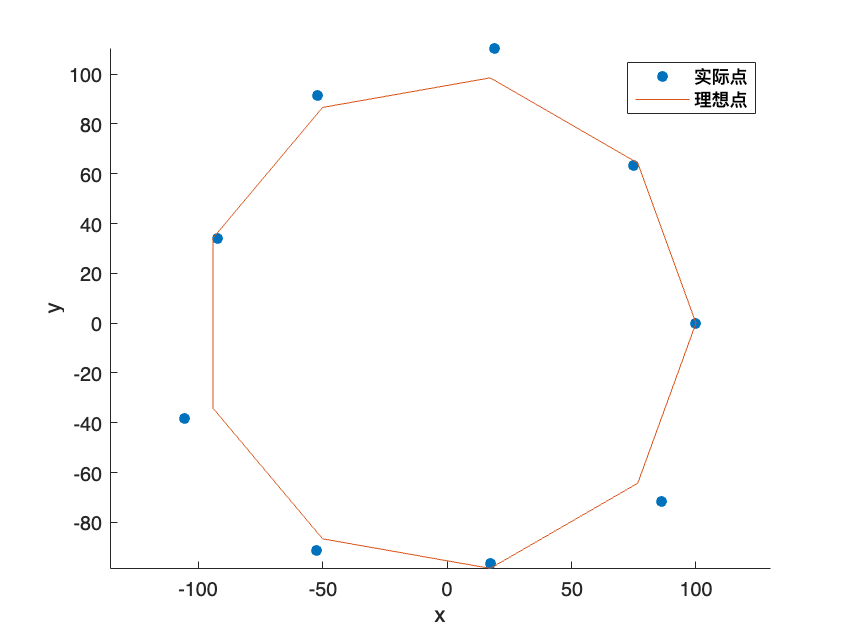


hold on
r = positions(:,1);
theta = positions(:,2);
axis equal
x0 = r.*cosd(theta);
y0 = r.*sind(theta);
scatter(x0,y0,'filled');

R = 100;
theta_ideal = 0:2*pi/9:9;
x_ideal = R*cos(theta_ideal);
y_ideal = R*sin(theta_ideal);
plot(x_ideal,y_ideal)


xlabel("x");
ylabel("y")
legend(["实际点","理想点"])

d = sum_distance(positions(:,1)',deg2rad(positions(:,2)'));
